# Assignment #3: A-ECMS

**Project overview**

This Live Script implements an Adaptive Equivalent Consumption Minimisation Strategy (A-ECMS) for the parallel hybrid electric vehicle (HEV) introduced in Lab 02. Unlike the offline ECMS, which requires the equivalence factor s to be calibrated on a specific driving cycle, the A-ECMS updates s online using proportional feedback on the battery State of Charge (SOC). This allows the strategy to deal with unknown future driving conditions while still enforcing approximate charge-sustaining behaviour over the mission.

The equivalence factor is updated every T_update seconds (time-based variant) or every d_update metres travelled (distance-based variant) according to the law $s_{n+1} = (s_n + s_{n-1})/2 + k_p * (\sigma_0 - \sigma(t))$, where sigma_0 = 0.6 is the target SOC and k_p is the proportional gain. The arithmetic mean of the last two values acts as a first-order low-pass filter on s and damps oscillations triggered by sudden SOC excursions.

## Group information

Group number: 46

Students:

- Matteo Canestrini, s349238

- Dennis Bettinsoli, s357720

- Simone Massucco, s357725

## Load the cycle and vehicle data

The simulation environment requires three input groups. The vehicle data (vehData.mat) is loaded and rescaled via scaleVehData to the sizing of this lab (engine power 118 kW, electric motor power 27 kW, battery capacity 2.1 kWh): the rescaling preserves the shape of the engine fuel map and of the e-machine efficiency map but scales the maximum torque / power envelopes accordingly. The transmission control data is also loaded for the gear-shift logic embedded in the powertrain model.

Five driving cycles are loaded as .mat files: Turin Test (the main tuning cycle, which mixes urban, suburban and motorway segments), and the three Artemis cycles (Urban AUDC, Rural ARDC, Motorway AMDC) used for validation. Every cycle stores a column vector of speed (km/h), of acceleration (m/s^2) and of time (s).

An optional preview block produces a tiled plot of speed and acceleration for the three Artemis cycles.

close all
clc
clear

addpath(genpath(fullfile("..", "Common")));

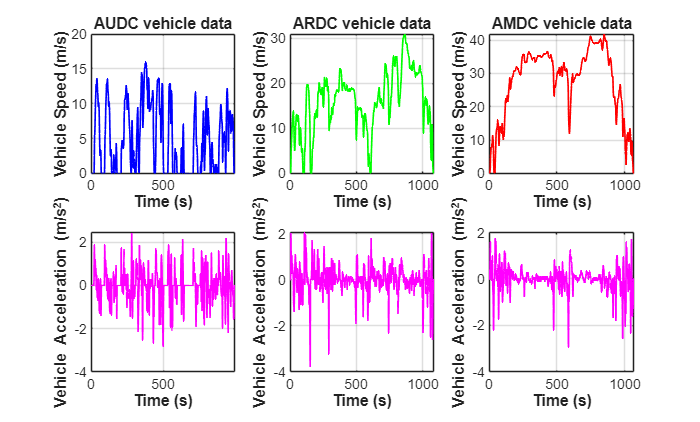


% Initialization
Turin = load("TurinTest.mat");
AMDC = load("AMDC.mat");
ARDC = load("ARDC.mat");
AUDC = load("AUDC.mat");

% % Canvas for cycles % % %

tur = tiledlayout(2,1);                   % figures layout
speed_Turin = Turin.speed_km_h / 3.6;

nexttile(1)
plot(Turin.time_s,speed_Turin, 'LineWidth',1, "LineStyle","-",'Color',"k")
grid on, box on
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Speed (m/s)","FontWeight","bold")
xlim ([0 length(speed_Turin)])

nexttile(2)
plot(Turin.time_s, Turin.acceleration_m_s2, "LineWidth",1, "LineStyle","-","Color","m")
grid on, box on
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Acceleration (m/s^2)","FontWeight","bold")
xlim ([0 length(Turin.acceleration_m_s2)])

Art = tiledlayout(2,3);                   % figures layout
speed_AUDC = AUDC.speed_km_h / 3.6;
speed_ARDC = ARDC.speed_km_h / 3.6;
speed_AMDC = AMDC.speed_km_h / 3.6;

nexttile(1)
plot(AUDC.time_s,speed_AUDC, 'LineWidth',1, "LineStyle","-",'Color',"b")
grid on, box on
title('AUDC vehicle data')
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Speed (m/s)","FontWeight","bold")
xlim ([0 length(speed_AUDC)])

nexttile(4)
plot(AUDC.time_s, AUDC.acceleration_m_s2, "LineWidth",1, "LineStyle","-","Color","m")
grid on, box on
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Acceleration (m/s^2)","FontWeight","bold")
xlim ([0 length(AUDC.acceleration_m_s2)])

nexttile(2)
plot(ARDC.time_s,speed_ARDC, 'LineWidth',1, "LineStyle","-",'Color',"g")
grid on, box on
title('ARDC vehicle data')
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Speed (m/s)","FontWeight","bold")
xlim ([0 length(speed_ARDC)])

nexttile(5)
plot(ARDC.time_s, ARDC.acceleration_m_s2, "LineWidth",1, "LineStyle","-","Color","m")
grid on, box on
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Acceleration (m/s^2)","FontWeight","bold")
xlim ([0 length(ARDC.acceleration_m_s2)])

nexttile(3)
plot(AMDC.time_s,speed_AMDC, 'LineWidth',1, "LineStyle","-",'Color',"r")
grid on, box on
title('AMDC vehicle data')
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Speed (m/s)","FontWeight","bold")
xlim ([0 length(speed_AMDC)])

nexttile(6)
plot(AMDC.time_s, AMDC.acceleration_m_s2, "LineWidth",1, "LineStyle","-","Color","m")
grid on, box on
xlabel("Time (s)","FontWeight","bold")
ylabel("Vehicle Acceleration (m/s^2)","FontWeight","bold")
xlim ([0 length(AMDC.acceleration_m_s2)])


veh = load("vehData.mat");                      % import the vehicle data
veh = scaleVehData(veh,118000,27000,2100);      % scale the data

## Objective

The goal of this assignment is twofold. First, develop a time-based A-ECMS controller and tune its proportional gain k_p on the Turin Test cycle so that the final SOC falls inside the charge-sustaining band [0.58, 0.62]. Beyond final SOC, the SOC trajectory must remain inside the physical battery bounds [0.40, 0.80] and the equivalence factor must remain within +/-50% of s_0 to guarantee a well-behaved (non-aggressive) update law.

Second, validate the tuned controller on three Artemis cycles that span very different traffic conditions (urban, rural, motorway). The aim is to assess how a single k_p value generalises across cycles with significantly different power-demand statistics from the one used for tuning. A distance-based variant of the controller is also developed and compared, replacing the time counter with a distance counter that triggers every d_update = 1 km. The analysis focuses on three key indicators: final SOC, evolution of the equivalence factor s(t), and fuel consumption / fuel economy on every cycle.

## Tuning on the Turin Test cycle

The proportional gain is swept considering 5 values containing the values we obtained to be the most suitable and two extreme cases. The full set is [0.82, 1.84, 1.92, 2.05, 2.9]. For every candidate value the full Turin Test cycle is simulated with an initial equivalence factor s_0 = 2.5645 (the value calibrated on the WLTP in Lab 02). simLoop is called with no_fig = 1, which disables both the figure generation and the controller warnings to keep the tuning faster.

**Validity flags collected for every k_p**

- Final_OK: SOC(t_f) lies inside the charge-sustaining target band [0.58, 0.62].

- Bounds_OK: SOC(t) stays inside the physical battery bounds [0.40, 0.80] for the whole cycle.

- value_s_OK: the final s deviates by less than 50% from s_0, i.e. s_final lies in [0.5*s_0, 1.5*s_0].

After the sweep the optimal k_p is selected with a two-stage rule: among the values that satisfy the flag final_SOC, pick the one minimising the percentage variation of equivalence factor s trajectory; if no value satisfies the flag, fall back to the minimum |SOC(t_f) - 0.6| criterion. We chose this criteria to improve the smoothness of our controller and avoid wide oscillations over the cycle. 

% Initialize the controller parameters
s_0 = 2.5645;
T_update = 60;      % Time update interval for the simulation
kp_vec = [0.82, 1.84, 1.92, 2.05, 2.9];    % set of kp
N = numel(kp_vec);

s_lower = s_0 - 0.5 * s_0;
s_upper = s_0 + 0.5 * s_0;

% Preallocate
SOC_sim_Tur_all   = cell(N,1);
s_array_Tur_all   = cell(N,1);
SOC_final_all     = zeros(N,1);
SOC_min_all       = zeros(N,1);
SOC_max_all       = zeros(N,1);
s_final_all       = zeros(N,1);
fuel_econ         = zeros(N,1);
s_var_percent_all = zeros(N,1);
final_ok          = false(N,1);
bounds_ok         = false(N,1);
value_s_final_ok  = false(N,1);
Results_Tur       = table();

colors = lines(N);

%% Simulation loop over kp values
for i = 1:N
    kp = kp_vec(i);
    fprintf('Running simulation %d/%d with kp = %g ...\n', i, N, kp);

    label = sprintf('Turin - kp = %g', kp);

    [SOC_sim_Tur, s_array_Tur, ~, ~, T_row, ~] = simLoop(Turin, s_0, kp, T_update, veh, label, 1);

    % Table of results' Turin test ( fuel consumption, fuel economy, final SOC, final s)
    Results_Tur = [Results_Tur; T_row];

    fuel_econ(i) = Results_Tur{i,3};

    SOC_sim_Tur_all{i} = SOC_sim_Tur;
    s_array_Tur_all{i} = s_array_Tur;

    % Final-value check (charge sustaining)
    SOC_final_all(i) = SOC_sim_Tur(end);
    final_ok(i)      = (SOC_final_all(i) >= 0.58) && (SOC_final_all(i) <= 0.62);

    % Trajectory check (physical battery limits)
    SOC_min_all(i) = min(SOC_sim_Tur);
    SOC_max_all(i) = max(SOC_sim_Tur);
    bounds_ok(i)   = (SOC_min_all(i) >= 0.40) && (SOC_max_all(i) <= 0.80);

    % Final value of equivalence factor s check
    s_final_all(i)      = s_array_Tur(end);
    value_s_final_ok(i) = (s_final_all(i) < (s_0 + 0.5*s_0)) && (s_final_all(i) > (s_0 - 0.5*s_0));

    % Percentage of equivalence factor trajectory variation
    s_var_percent_all(i) = (max(s_array_Tur) - min(s_array_Tur)) / s_0 * 100;

    
end

Running simulation 1/5 with kp = 0.82 ...
Running simulation 2/5 with kp = 1.84 ...
Running simulation 3/5 with kp = 1.92 ...
Running simulation 4/5 with kp = 2.05 ...
Running simulation 5/5 with kp = 2.9 ...


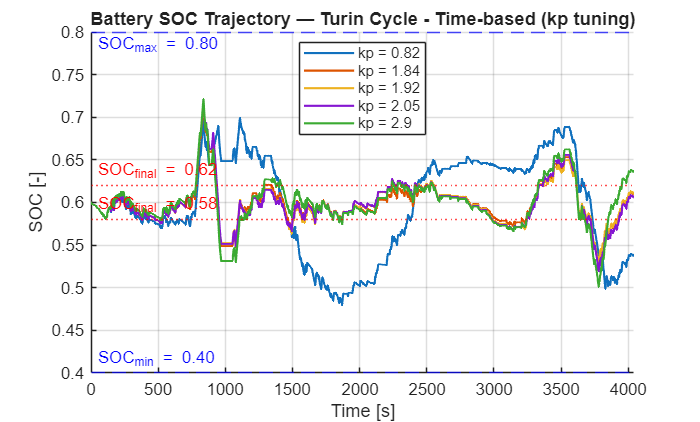


time_Tur = Turin.time_s;
time_Tur(end+1) = time_Tur(end) + 1;    % time modification for the plot

%% Plot 1: SOC trajectories for all kp values
figure('Name','Turin cycle - SOC vs kp','NumberTitle','off')
hold on
legend_entries = cell(N,1);
for i = 1:N
    plot(time_Tur, SOC_sim_Tur_all{i}, 'Color', colors(i,:), 'LineWidth', 1.3);
    legend_entries{i} = sprintf('kp = %g', kp_vec(i));
end
yline(0.40, 'b--', 'SOC_{min} = 0.40', 'LabelHorizontalAlignment','left')
yline(0.80, 'b--', 'SOC_{max} = 0.80', 'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom')
yline(0.62, 'r:',  'SOC_{final} = 0.62', 'LabelHorizontalAlignment','left')
yline(0.58, 'r:',  'SOC_{final} = 0.58', 'LabelHorizontalAlignment','left')
xlabel('Time [s]')
ylabel('SOC [-]')
title('Battery SOC Trajectory — Turin Cycle - Time-based (kp tuning)')
legend(legend_entries, 'Location','best')
xlim([0 length(time_Tur)])
grid on
hold off

This figure overlays the SOC trajectories of the five tuning simulations on the Turin cycle for **kp ∈ {0.82, 1.84, 1.92, 2.05, 2.9}**. The Turin cycle lasts approximately 4000 s and features a mixed profile (urban + rural + highway), making it highly representative of a real-world driving mission in Turin.

- **kp = 0.82:** Very low gain; the correction on *s* is slow and insufficient. The SOC progressively drifts away from the target: after peaking at around 0.70 near t = 800 s, it drops sharply to ~0.47, before slowly recovering to a final SOC (*SOC_final*) of ≈ 0.68. This value is clearly outside the [0.58, 0.62] charge-sustaining band; the controller behaves almost like a fixed-factor ECMS.

- **kp = 1.84:** Moderate, well-damped oscillations with a final SOC of about 0.609, comfortably inside the [0.58, 0.62] band. It satisfies the charge-sustaining criterion and, among the valid candidates, shows the lowest percentage variation of the s trajectory, which makes it the optimal selection.

- **kp = 1.92:** Behaviour very close to kp = 1.84, with a final SOC of about 0.610. It is also a valid candidate, but its s trajectory varies slightly more, so it is not selected as the optimum.

- **kp = 2.05:** Shows similar behavior to 1.92 with *SOC_final* ≈ 0.58, but with slightly more pronounced excursions.

- **kp = 2.90:** Wide SOC oscillations in the middle of the cycle (dropping down to ~0.53) followed by a recovery, with *SOC_final* ≈ 0.61. While it stays within the final band, it exhibits much wider oscillations in *s*.

The [0.58, 0.62] charge-sustaining band is indicated by the red dashed lines; the physical limits [0.40, 0.80] are never reached by any of the tested kp values.

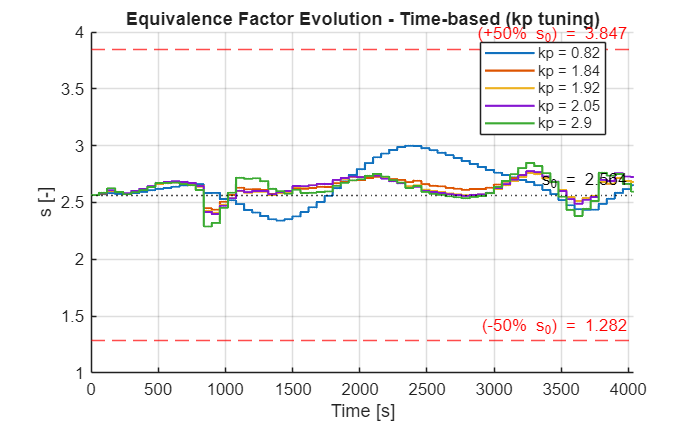


%% Plot 2: s evolution for all kp values
time_Tur_s = time_Tur;
time_Tur_s(end) = [];

figure('Name','s evolution vs kp','NumberTitle','off')
hold on
for i = 1:N
    plot(time_Tur_s, s_array_Tur_all{i}, 'Color', colors(i,:), 'LineWidth', 1.3);
end
yline(s_lower, 'r--', sprintf('(-50%% s_0) = %.3f', s_lower));
yline(s_upper, 'r--', sprintf('(+50%% s_0) = %.3f', s_upper));
yline(s_0,     'k:',  sprintf('s_0 = %.3f', s_0));
xlabel('Time [s]')
ylabel('s [-]')
title('Equivalence Factor Evolution - Time-based (kp tuning)')
legend(legend_entries, 'Location','best')
xlim([0 length(time_Tur_s)])
grid on
hold off

This chart tracks the evolution of the equivalence factor *s* over the Turin cycle for the same five kp values. The ±50% boundaries relative to *s₀* = 2.5645 are [1.282, 3.847].

- All profiles start at *s₀* = 2.5645 and never breach the safety bounds; therefore, saturation on *s* is never triggered during this cycle.

- **kp = 0.82:** *s* varies slowly and monotonically toward higher values (ending around ~2.85) without ever returning toward *s₀*. This explains the SOC drift: the controller does not correct enough.

- **kp = 1.84:** Tightly bounded variation centered around s_0, with a percentage variation of about 12.8%. This is the smoothest profile among the valid candidates, which confirms its selection based on minimizing the percentage variation of s.

- **kp = 1.92:** Almost coincident with kp = 1.84 but with a slightly larger variation, about 13.5%; it remains a valid candidate but it is not the optimum.

- **kp = 2.05:** Similar to 1.92 but with slightly wider excursions.

- **kp = 2.9:** Wide excursions in *s* (minimum ~2.28, maximum ~2.84), resulting in the most oscillatory profile. The controller is over-reactive: minor SOC deviations trigger massive corrections in *s*, risking instability on less balanced cycles.

% % Summary table % %
fprintf('\n--- kp tuning summary ---\n');


--- kp tuning summary ---


T_kp_results = table(kp_vec(:), SOC_final_all, final_ok, SOC_min_all, SOC_max_all, bounds_ok, s_final_all, value_s_final_ok, s_var_percent_all, ...
    'VariableNames', {'kp','SOC_final','Final_OK','SOC_min','SOC_max','Bounds_OK', 's_final', 'value_s_OK', 's_percent_var'});
disp(T_kp_results)

     kp     SOC_final    Final_OK    SOC_min    SOC_max    Bounds_OK    s_final    value_s_OK    s_percent_var
    ____    _________    ________    _______    _______    _________    _______    __________    _____________

    0.82     0.53681      false       0.4795    0.69895      true       2.6508       true           25.699    
    1.84     0.60918      true       0.52959    0.71737      true       2.6807       true           12.843    
    1.92     0.61016      true       0.53057    0.72083      true       2.6789       true           13.512    
    2.05      0.6055      true       0.51932      0.721      true       2.7254       true           14.632    
     2.9     0.63536      f

%% --- OPTIMIZATION SEARCH (Time-Based) ---

% Find the original indices that satisfy all validity criteria
valid_idx = find(final_ok);

if isempty(valid_idx)
    % Fallback: If no candidate satisfies all criteria, pick the one with SOC closest to 0.60
    [~, idx_opt] = min(abs(SOC_final_all - 0.60));
else
    % Extract the 's' variation percentage ONLY for the valid candidates
    value_s_percent = s_var_percent_all(valid_idx);
    
    % Search for the minimum 's' variation among them to ensure smoothness
    [~, best_valid_idx] = min(value_s_percent);
    
    % Trace back to the absolute original index to avoid array size mismatch
    idx_opt = valid_idx(best_valid_idx);
end

% Extract the final optimal values
kp_opt = kp_vec(idx_opt);                 % evaluation of optimal kp for time-based


fprintf('\n--- The optimal kp (Time-Based) found is: %g, with SOC_final = %.4f and s_final = %.4f ---', kp_opt, SOC_final_all(idx_opt), s_final_all(idx_opt));


--- The optimal kp (Time-Based) found is: 1.84, with SOC_final = 0.6092 and s_final = 2.6807 ---

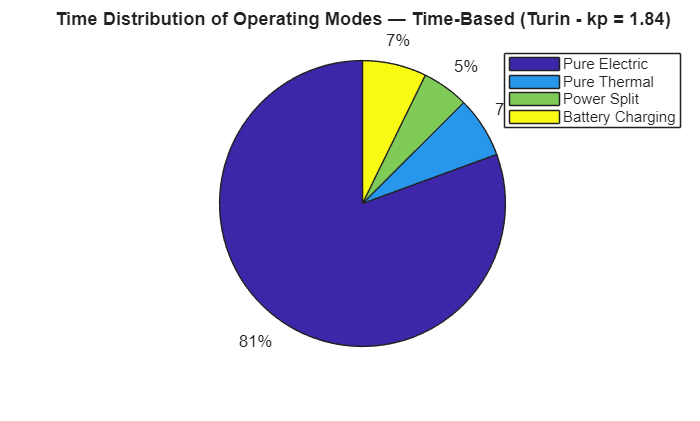

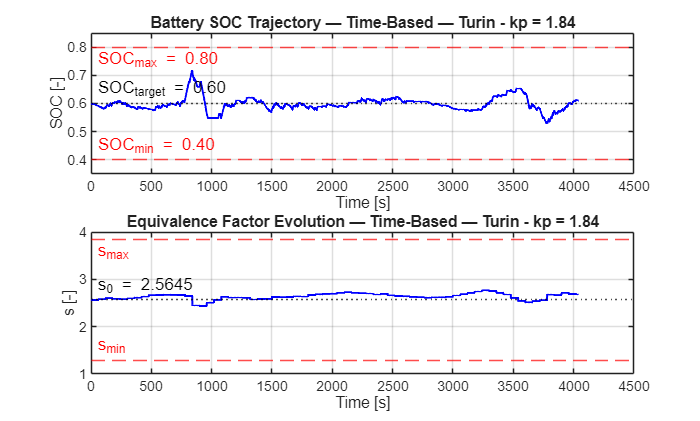

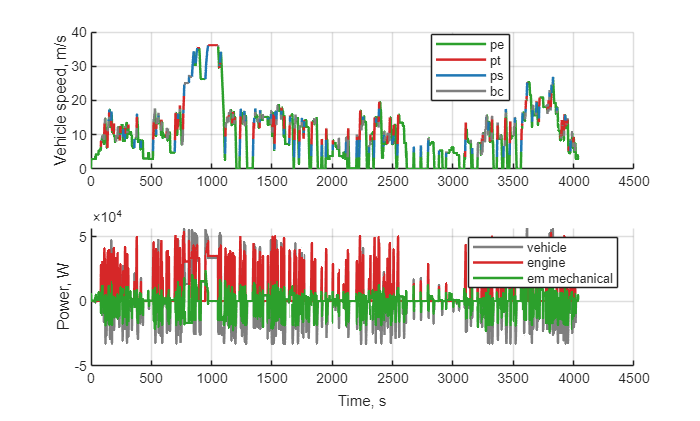


label = sprintf('Turin - kp = %g', kp_opt);
[SOC_sim_Tur, s_array_Tur, prof_Tur, mf_eq_Tur, Results_Tur] = simLoop(Turin, s_0, kp_opt, T_update, veh, label, 0);

The pie chart shows the time-based distribution of the vehicle's operating modes on the Turin cycle using the optimal time-based controller:

- **Pure Electric: 81%** — Clear dominance of EV mode. The Turin cycle includes low-speed urban segments where the ECMS favors the electric motor, which carries a zero equivalent fuel cost when *s* is close to *s₀* and the SOC is on target.

- **Battery Charging: 7%** — The internal combustion engine (ICE) generates extra power to recharge the battery; this occurs during mid-speed phases.

- **Power Split: 5%** — Combined effort from both powertrains under intermediate load conditions.

- **Pure Thermal: 7%** — Exclusive use of the ICE, kept to a minimum over a mixed cycle.

The figure illustrates the time-domain evolution of the battery State of Charge (SOC) and the equivalence factor ( $s$ ) on the Turin cycle, applying the optimal proportional gain $k_p = 1.84$ .

As visible in the upper subplot, the SOC trajectory is highly dynamic. It experiences a significant peak around t = 850 s, reaching approximately 0.71, followed by a couple of pronounced dips (down to roughly 0.54) during the more demanding phases of the cycle. Despite these wide excursions, the controller successfully maintains the SOC strictly within the physical safety boundaries of [0.40, 0.80]. More importantly, it demonstrates excellent charge-sustaining capabilities, recovering the battery charge to finish the cycle within the required [0.58, 0.62] target band.

The lower subplot reveals the underlying mechanism of the A-ECMS. The equivalence factor s dynamically adapts to the SOC tracking error. When the SOC is high (e.g., at 800 s), s drops to lower the equivalent cost of electricity, aggressively promoting Pure Electric mode to deplete the excess charge. However, when the SOC drops below the target, s smoothly rises to favor the internal combustion engine and battery charging.

Crucially, while the variations in SOC are relatively wide, the control action itself remains remarkably clean. The trajectory of s does not exhibit high-frequency "chattering" or erratic jumps. It acts as a smooth, well-damped low-pass filter, staying comfortably far from the $\pm 50\%$ saturation limits ( $s_{min$ and $s_{max}$ ). This confirms that the selected $k_p = 1.84$ is not overly aggressive.

**Power Profiles **The figure reports the vehicle speed coloured by operating mode (top) and the mechanical power of vehicle, engine and e-machine (bottom). On the Turin cycle the road-load power stays within roughly (-32 +55) kW. The engine power (red) is delivered in short bursts that coincide with the mid- and high-speed segments and drops to zero during the long low-load urban phases (for example around t = 2600-3100 s), consistent with the 81% pure-electric share. The e-machine power (green) continuously alternates between positive values (traction assist) and negative values (regenerative braking, visible whenever the grey vehicle power becomes negative). On this balanced mixed cycle the controller therefore concentrates the engine into discrete, efficient working intervals and delegates the low-power transients and the brake-energy recovery to the electric machine.

disp(Results_Tur)

            Cycle            Fuel Consumption (kg)    Fuel Economy (l/100km)    SOC_final    s_final
    _____________________    _____________________    ______________________    _________    _______

    {'Turin - kp = 1.84'}           1.4992                    4.4412             0.60918     2.6807 



**Output of the tuning step**

The optimal k_p picked by the selection rule is reported on the command line together with its row of Results_Tur (fuel consumption, fuel economy, final SOC). The controller achieves a Fuel Economy of `4.44 l/100km` (with a total fuel consumption of 1.50 kg). This indicates that the ECMS efficiently distributes the power demand between the internal combustion engine and the electric machine across the mixed segments of the cycle.

Regarding the boundary conditions, the final State of Charge settles at 0.609. This safely satisfies the strictly enforced charge-sustaining band of $[0.58, 0.62]$. Simultaneously, the final equivalence factor (s) concludes at 2.68, indicating a moderate correction from the initial baseline of $s_0 = 2.5645$.

During the calibration phase, other $k_p$ values yielded a final SOC that was mathematically closer to the absolute 0.60 target. However, forcing the final SOC to exactly 0.60 required significantly higher proportional gains. Those higher gains forced the controller into an overly aggressive state, resulting in high-amplitude oscillations in both the s and SOC trajectories. Such aggressive control actions drastically degrade the powertrain's stability and overall efficiency due to continuous switching between pure electric and battery charging modes.

Therefore, these results confirm that $k_p = 1.84$ is the optimal compromise: it accepts a slight final SOC offset (while remaining strictly within the valid limits) in exchange for a much smoother and highly efficient energy management policy.

## Test the time-based A-ECMS on the test cycles

The tuned k_p_opt is now applied to the three Artemis cycles without any further adaptation. For every cycle the simulation is launched with no_fig = 0, so that the full plots are generated, and with a fresh controller state (s_n = s_prev = s_0, t_c = 1): no information about the previous run leaks into the next one.

**Cycle preparation**

- AUDC is repeated 5 times via repeatedMission to obtain a representative urban mission of about 80 minutes.

- ARDC is repeated 2 times via repeatedMission to span about 35 minutes of mixed rural driving.

- AMDC is used as is: a single motorway mission of about 18 minutes is already long enough.

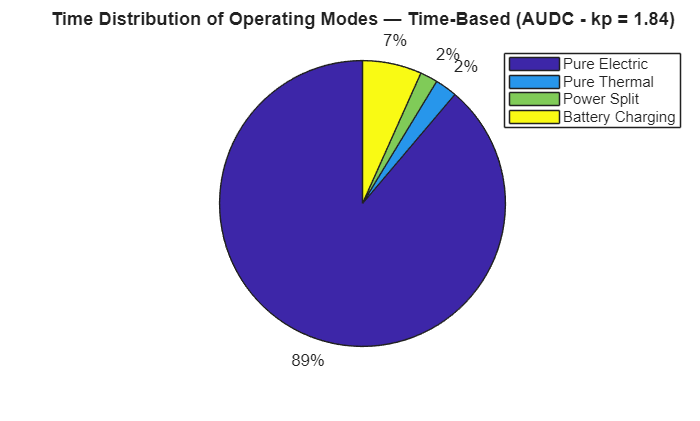

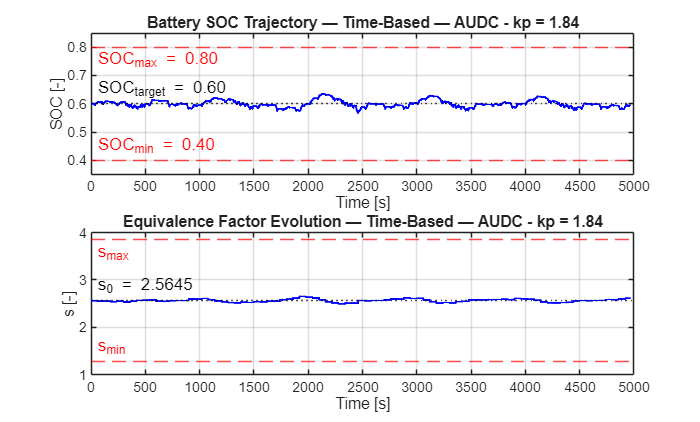

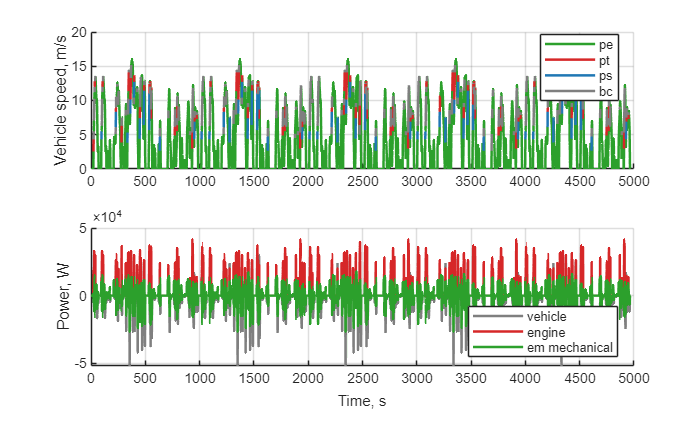

% % % Urban validation % % %
AUDC_5x = repeatedMission(AUDC, 5);

label = sprintf('AUDC - kp = %g', kp_opt);
[SOC_sim_Urban, s_array_Urban, prof_Urban, mf_eq_Urban, Results_Urban, fig_Urban] = simLoop(AUDC_5x, ...
 s_0, kp_opt, T_update, veh, label, 0);

Modal distribution over the urban cycle repeated 5 times (~5000 s):

- **Pure Electric: 89%** — The EV share is even higher than in the Turin cycle. The AUDC urban cycle is characterized by low speeds, frequent stops, and light accelerations; power demand is almost always met by the electric motor without involving the engine.

- **Pure Thermal: 2%, Power Split: 2%, Battery Charging: 7%** — The ICE is practically idle. This is expected: the ECMS minimizes equivalent consumption, and during a slow urban cycle, the cost of fuel almost always exceeds the equivalent cost of electricity.

The SOC oscillates almost cyclically around the 0.60 target with a tight amplitude (roughly ±0.06). These periodic oscillations correspond to the five repetitions of the AUDC cycle; the repeating structure is highly apparent in the evolution of *s*. The factor *s* stays locked close to *s₀* with only minor deviations, never nearing the ±50% limits. The final SOC hits approximately 0.595, demonstrating excellent charge-sustaining behavior. The time-based controller performs well on urban cycles because the average power demand is low and SOC deviations are moderate, meaning the kp = 1.84 gain provides more than enough corrective authority.

**Power Profiles: ** The road-load power is the lowest of all the cycles (mostly within -52 + 40 kW). The engine (red) intervenes only sporadically, with short peaks around 30 kW, while the e-machine (green) covers almost the entire traction and braking demand, consistent with the 89% pure-electric share. The frequent negative spikes of the grey vehicle power (down to about -50 kW) correspond to the many braking events of the stop-and-go profile, recovered by the e-machine as regenerative power. In an urban environment the powertrain therefore behaves essentially as a pure EV, with the engine acting only as a backup.

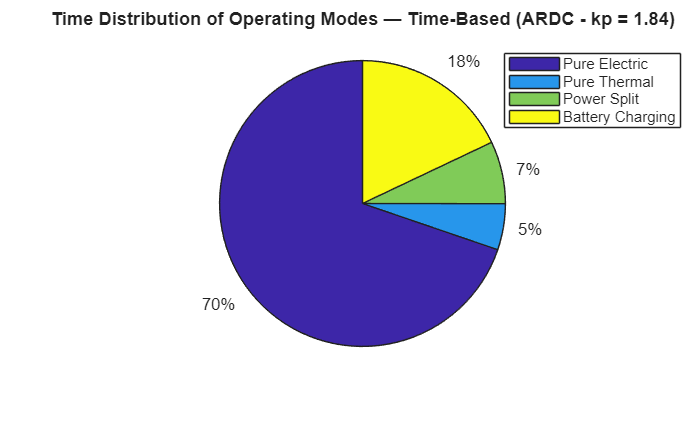

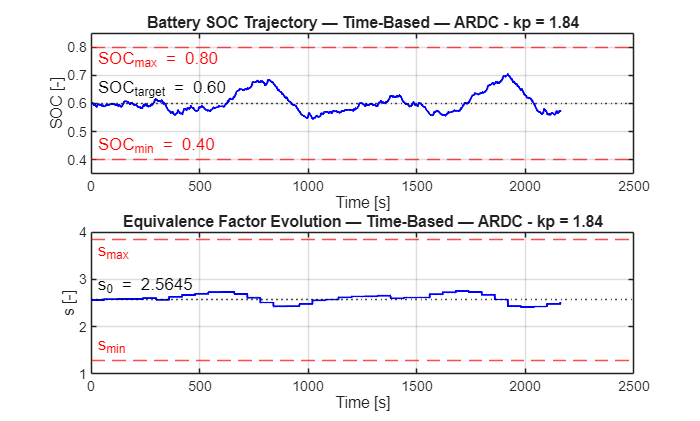

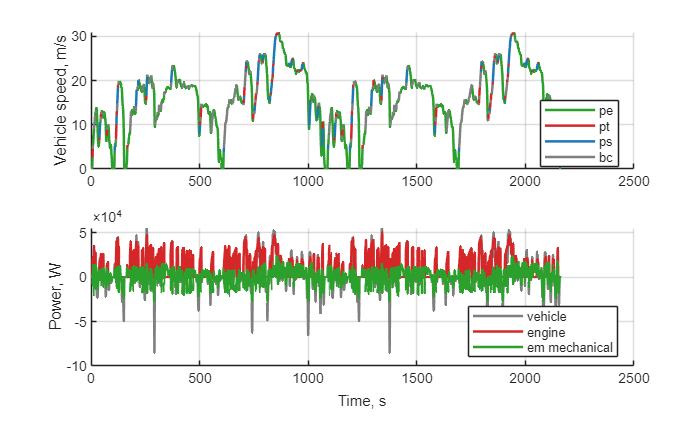

% % % Rural validation % % %
ARDC_2x = repeatedMission(ARDC, 2);

label = sprintf('ARDC - kp = %g', kp_opt);
[SOC_sim_Rural, s_array_Rural, prof_Rural, mf_eq_Rural, Results_Rural, fig_Rural] = simLoop(ARDC_2x, ...
    s_0, kp_opt, T_update, veh, label, 0);

Modal distribution over the rural cycle repeated twice (~2300 s):

- **Pure Electric: 70%** — The EV share remains dominant but is lower than in the AUDC. At extra-urban speeds (70–100 km/h), power demand scales up, requiring more frequent engine engagement.

- **Pure Thermal: 5%** — Significantly higher engine share than in the AUDC. At sustained speeds, the ICE operates within its high-efficiency window, lowering its cost in the ECMS cost function.

- **Battery Charging: 18%** — High charging share: the engine provides extra power to recharge the battery during mid-to-high speed phases. This serves as the primary mechanism for SOC recovery.

- **Power Split: 7%** — Marginal.

The SOC oscillates between ~0.54 and ~0.70, well within physical limits. Its evolution is highly regular, tracing an almost sinusoidal pattern that tracks the two ARDC repetitions. The factor *s* also stays very close to *s₀*, with excursions of just a few hundredths. The final SOC settles at around 0.574, marginally below the charge-sustaining band.

**Power Profiles:** At extra-urban speeds the road-load power rises, with traction peaks near 50 kW and braking events below -84 kW. The engine (red) is engaged far more regularly than in the urban cycle and reaches higher power, since sustained mid-speed cruising brings it into its high-efficiency region; the e-machine (green) still provides assist and regeneration but with a smaller relative weight. This is coherent with the modal split (70% pure electric, 18% battery charging): the engine both propels the vehicle and recharges the battery during the cruise phases.

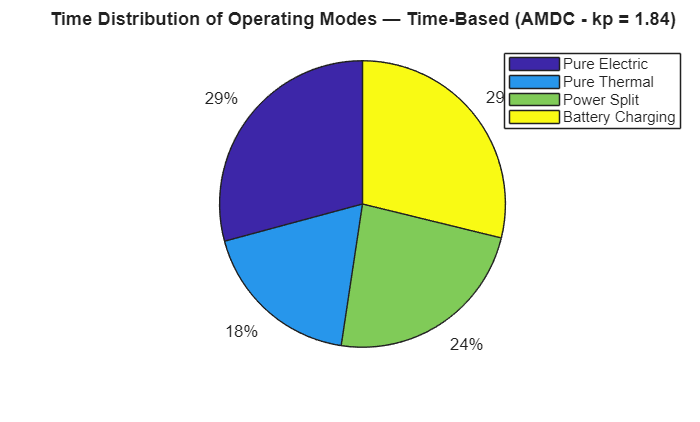

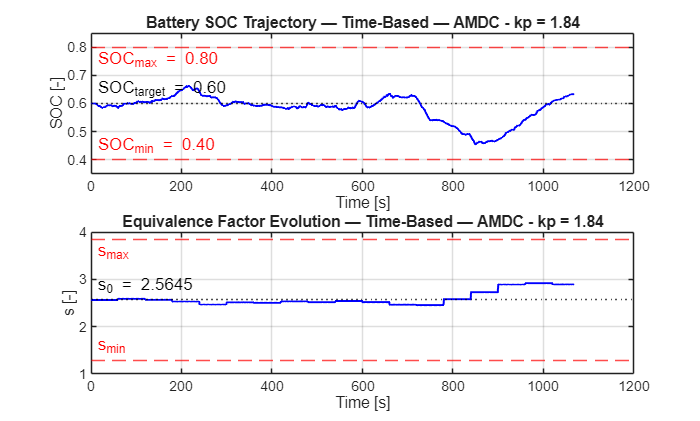

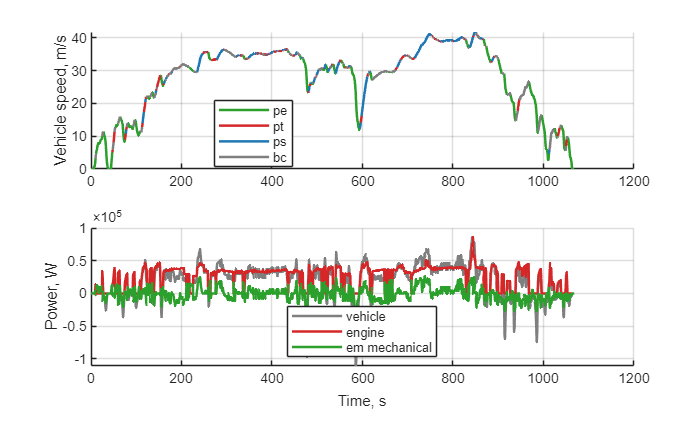

% % % Motorway validation % % %
label = sprintf('AMDC - kp = %g', kp_opt);
[SOC_sim_Mot, s_array_Mot, prof_Mot, mf_eq_Mot, Results_Mot, fig_Mot] = simLoop(AMDC, s_0, ...
    kp_opt, T_update, veh, label, 0);

Modal distribution over the highway cycle (single run, ~1200 s):

- **Pure Electric: 29%** — The EV share drops drastically compared to the other cycles. At 120–130 km/h, the torque demand almost always exceeds the capability of the electric motor.

- **Pure Thermal: 18%, Power Split: 24%, Battery Charging: 29%** — The combustion engine dominates; the combined share of ICE-active modes reaches 71%. The high charging share (29%) indicates that the controller actively attempts to recharge the battery during highway cruising, mirroring the increase in *s.*

This is the most critical plot of the entire time-based analysis. Starting at 0.60, the SOC tracks near the target for the first 500 s before taking a sharp dive down to roughly 0.46 around t = 850 s. The controller responds by driving up *s* (from ~2.56 to ~3.0 in the second half of the cycle), shifting the optimization policy toward heavy engine usage to recharge the battery. However, the cycle ends before the SOC can recover to its target, leaving *SOC_final* ≈ 0.63 — just above the [0.58, 0.62] band.

This failure is due to several factors:

The AMDC cycle is short (~1200 s), offering only about 20 updates for *s*.

The average power demand is very high and sustained, causing a rapid battery depletion.

Once *s* climbs to ~3.0, the controller overcharges the battery in the final phase, causing a late overshoot in the final SOC.

While the factor *s* remains within the ±50% boundaries (*s_max* = 3.847), it approaches the upper limit, indicating extreme corrective effort.

**Power split.** The power scale is one order of magnitude larger than in the other cycles: the road-load power reaches about 86 kW and -110 kW. The engine power (red) is no longer delivered in bursts but is sustained continuously at roughly 30-40 kW for the whole central part of the cycle, which is the physical reason behind the low pure-electric share (29%) and the high combined share of engine-on modes (about 71%). The e-machine (green) only adds a limited contribution, since the torque demand at 120-130 km/h exceeds what it can supply alone; the large negative grey spikes at the end correspond to the final deceleration, partially recovered by regenerative braking. This sustained, high-power operation is exactly what depletes the battery and forces the controller to raise s in order to recharge it.

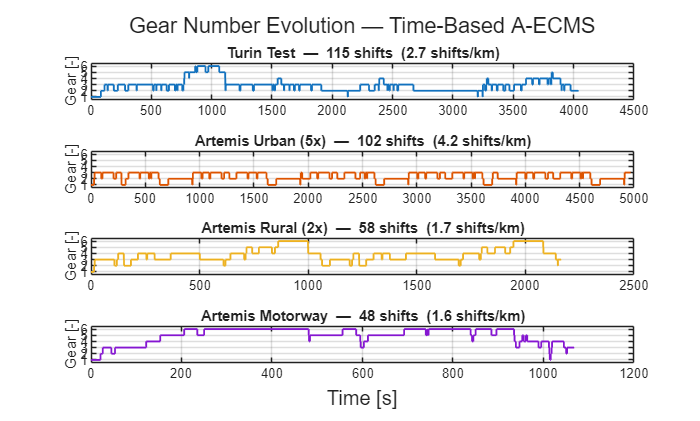

%% Gear profile — all four cycles (time-based A-ECMS)
gears    = {prof_Tur.vehPrf.gearNumber, prof_Urban.vehPrf.gearNumber, ...
            prof_Rural.vehPrf.gearNumber, prof_Mot.vehPrf.gearNumber};
missions = {Turin, AUDC_5x, ARDC_2x, AMDC};
names    = {'Turin Test', 'Artemis Urban (5x)', 'Artemis Rural (2x)', 'Artemis Motorway'};
cols     = lines(4);

figure('Name','Gear profile - Time-based cycles','NumberTitle','off')
tg = tiledlayout(4,1);

for i = 1:4
    g  = gears{i};
    t  = missions{i}.time_s;
    d  = trapz(t, missions{i}.speed_km_h/3.6) / 1000;   % distance [km]
    nS = sum(diff(g) ~= 0);                             % n° of shifts

    nexttile
    stairs(t, g, 'LineWidth', 1.1, 'Color', cols(i,:))
    grid on, box on
    ylim([0.5 6.5]); yticks(1:6); ylabel('Gear [-]')
    title(sprintf('%s  —  %d shifts  (%.1f shifts/km)', names{i}, nS, nS/d))
end
xlabel(tg, 'Time [s]')
title(tg, 'Gear Number Evolution — Time-Based A-ECMS')


fprintf('\n--- Artemis Cycles'' Results  summary ---\n');


--- Artemis Cycles' Results  summary ---


T_all = [Results_Urban; Results_Rural; Results_Mot];
disp(T_all)

           Cycle            Fuel Consumption (kg)    Fuel Economy (l/100km)    SOC_final    s_final
    ____________________    _____________________    ______________________    _________    _______

    {'AUDC - kp = 1.84'}           0.77313                   4.0449             0.59529     2.6151 
    {'ARDC - kp = 1.84'}            1.0982                   4.0496             0.57352     2.5023 
    {'AMDC - kp = 1.84'}            1.5953                   6.8784             0.63285     2.8923 



**Gear-shifting behaviour.** The figure collects the gear-number trajectory of the four cycles obtained with the time-based controller; the number of gear changes and the shift rate per kilometre are reported in each subplot title. The gear-shift penalty added to the cost function keeps the transmission on a stable gear during steady phases, but the residual shifting remains strongly cycle-dependent. The Urban cycle is by far the most demanding for the transmission: the continuous stop-and-go forces the gear to oscillate almost permanently between 1st and 3rd, producing the highest number of shifts. The Turin cycle is intermediate, with the gear mostly held between 2nd and 4th and brief excursions to 5th-6th in the high-speed section around t = 900-1050 s. The Rural cycle is markedly smoother, the gear following the speed humps up to 5th-6th. The Motorway cycle is the most stable of all: the gear climbs monotonically to 5th-6th and stays there for almost the whole mission, with the lowest shift count. This ordering (Urban, then Turin, then Rural, then Motorway) shows that gear shifting, a key drivability indicator, is driven by the variability of the speed profile rather than by its average level, and that the ECMS, even with the shift penalty, still produces appreciable shifting activity on the most transient cycles.

## Analysis and Discussion (Time-Based)

The results in the previous table clearly highlight the strengths and the inherent limitations of using a fixed proportional gain tuned on a mixed cycle:

`AUDC (Urban Cycle, 5 Repetitions)`

- The controller performs exceptionally well in the urban environment, achieving the highest fuel efficiency among the tested cycles. Because the power demand in urban traffic is generally low, the electric motor can handle most of the traction efficiently. As confirmed by the plots, the SOC and s experience only minor, stable oscillations. This stability guarantees that the final SOC lands comfortably within the charge-sustaining band without requiring aggressive, fuel-consuming corrections from the engine.

`ARDC (Rural Cycle, 2 Repetitions)`

- During the rural cycle the fuel economy is slightly higher than in the urban and the final SOC hits the target almost perfectly. The plots justify this outcome: the extra-urban speeds provide a balanced power demand for the hybrid powertrain. Consequently, the equivalence factor s remains flat, allowing the engine to operate continuously in its optimal efficiency region while maintaining charge-sustaining behavior with minimal control effort.

`AMDC (Motorway Cycle, 1 Run)`

- The controller fails to sustain the charge on the highway cycle, with fuel consumption spiking and the final SOC ending slightly above the target band. The plots explain the physical reason behind this failure: sustained high-speed driving causes a rapid battery depletion. To counteract this massive SOC error, the controller increases s to force aggressive battery charging via the combustion engine. Because the AMDC cycle is short, the simulation ends while the controller is still in this heavy, inefficient charging phase, resulting in both a final SOC slightly above the band and a degraded fuel economy.

- **What happens if **$k_p
$** is very high? What happens if **$k_p
$**  is very low? Is there a trade-off in our objectives?**

The proportional gain `kp` dictates the controller's response: it determines how aggressively a deviation of the SOC from its target (0.60) translates into a correction of the equivalence factor `s`, thereby modifying the energy split strategy.

- **Low kp (e.g., 0.82):** The correction of `s` per unit of SOC error is minimal. The plot with the comparison of kps shows that the blue trajectory drifts away from *s₀* slowly and monotonically, never steering back toward the initial value. The direct consequence is that the SOC progressively drifts from the target, drifting to about 0.54 by the end of the cycle, well outside the [0.58, 0.62] band. The controller acts nearly like a fixed-gain ECMS, unable to adapt to the energy demand variations of the cycle.

- **High kp (e.g., 2.9):** The control action is aggressive -even minor SOC deviations prompt large swings in `s`. The plot llustrates that the green trajectory features the widest oscillations in `s` (ranging between ~2.05 and ~2.90). This induces heavy oscillations in the SOC as well, as the controller overcorrects, driving the dynamics close to limit-cycling behavior. On short cycles like the AMDC, an excessively high kp risks pushing `s` into its upper saturation limit (*s_max* = 3.847).

There is a fundamental trade-off between Charge-Sustaining reliability and Powertrain Stability. Our goal is to maintain the battery charge while minimizing fuel consumption. A highly reactive controller (high $k_p$ ) prioritizes the SOC target but ruins the stability of $s$; this erratic equivalence factor forces the engine to constantly switch between electric assist and battery charging. This continuous switching drastically degrades both vehicle drivability and overall fuel efficiency. Conversely, a lazy controller (low $k_p$ ) prioritizes smoothness, allowing the engine to operate steadily and efficiently, but completely fails the primary charge-sustaining objective.

The value $k_p = 1.84$ is selected as optimal exactly to balance this trade-off. It is the gain that simultaneously satisfies validity criteria ( $SOC_{final} \in [0.58, 0.62]$ ) while minimizing the percentage variation of the s profile.

- **Did your value of **$k_p
$**  "work well" for all three test cases (the Artemis cycle)?**

No. The controller demonstrated vastly different performance levels across the three cycles:

- **AUDC (Urban, ×5):** Outstanding performance. The SOC stays tightly bound within a narrow envelope (±0.06) centered at 0.60 throughout the entire run, with `s` remaining nearly flat. The final SOC lands right around 0.60. The 89% Pure Electric share shows that low power demands are consistently covered by the EM, with the engine intervening only on rare occasions. The urban cycle represents the most favorable scenario because the average power demand is low, keeping SOC deviations naturally small without requiring aggressive feedback.

- **ARDC (Rural, ×2):** Solid performance. SOC oscillate safely between 0.54 and 0.70 and the final SOC ≈ 0.574. The cyclic pattern is highly regular, and charge-sustaining targets are fully respected. The increased power demand at extra-urban speeds requires a more balanced activation of the engine (70% EV vs. 89% in the AUDC), but the controller successfully maintains the SOC near the target due to the sufficient duration of the cycle.

- **AMDC (Highway):** The controller does not fully re-enter the target band. The SOC dips to ~0.46 around t = 850 s, followed by a strong recovery that ends at a final SOC of ≈ 0.63, only slightly above the [0.58, 0.62] band. The factor`s` surges to ~3.0 by the end of the run (nearing its upper bound), but the cycle terminates before the SOC can settle back into the target band. This failure stems from structural differences between the AMDC and the tuning cycle. 

- **We suggested a tuning procedure based on enforcing a strict charge-sustaining behavior (**$\sigma_f \in [0.58, 0.62]$**) on a specific cycle. Could the behavior of the controller be improved by modifying the tuning procedure?**

The current procedure selects $k_p$ on the Turin cycle by minimizing the variation of $s$, subject to the final constraint $SOC_{final} \in [0.58, 0.62]$. While this ensures good performance on balanced cycles with moderate power demands, it fails to generalize to the AMDC due to the structural reasons noted above (bias toward the tuning cycle). The behavior of the controller could be significantly improved by modifying the tuning procedure in the following ways:

- **Multi-cycle Optimization:** Instead of calibrating kp on a single cycle, the optimization could utilize an objective function that aggregates final SOC deviations across a representative set of profiles, including different conditions. The resulting kp would yield a more robust compromise, automatically penalizing gains that perform well in urban settings but fail on highway segments.

- **Tuning criterion based on peak SOC deviation:** The current strategy looks exclusively at the final SOC value, ignoring the transient behavior. Introducing a strict constraint on the maximum intra-cycle excursion (e.g., $|SOC(t) - 0.60| \le 0.08$ for all t) would directly penalize and mitigate the severe dip seen in the AMDC, ensuring that the battery is never pushed dangerously close to its physical limits during the mission.

- **Is feedback on the SOC enough to develop an effective adaptive ECMS? Do you see room for improvement? At what cost (in terms of complexity)?**

Pure SOC feedback relies on a purely reactive control scheme: the adjustment to `s` only occurs after a deviation has already manifested. On stationary cycles of sufficient duration (AUDC, ARDC), this approach is adequate since deviations remain bounded and the controller has ample time to correct them. However, its fundamental limitation comes to light during brief, highly non-stationary power profiles like the AMDC. Specific Limitations of Pure SOC Feedback**:**

- **Lack of future demand anticipation:** The controller has no way of knowing whether the vehicle is entering a prolonged highway or coming to a stop. The same `kp` must handle both extremes blindly.

- **Inherent time delay:** the controller updates `s` every 60 seconds. Over a short 1200 s cycle, this leaves a wide window for substantial SOC error accumulation before any significant correction takes place.

**Room for Improvement:**

To overcome the limitations of a purely reactive system, the A-ECMS could be upgraded to a predictive architecture.

- **Route Preview:** By integrating GPS and ADAS (Advanced Driver Assistance Systems) data, the controller could anticipate upcoming speed limits, traffic conditions, and road topography. This allows the controller to preemptively adjust s before the SOC drops.

- **Driving Pattern Recognition:** Implementing machine learning algorithms to classify the driving environment in real-time (e.g., detecting if the car is currently in Urban Traffic or in Motorway). The controller could then dynamically switch the baseline s_0 or the gain kp to values pre-optimized for that specific condition, rather than relying on a single compromise value tuned on a mixed cycle.

These improvements come at a severe cost in terms of system complexity, hardware requirements, and computational load:

- Predictive algorithms, especially those running optimizations over a future time horizon, require exponentially more processing power than the simple algebraic update law $s_{n+1} = \frac{s_n + s_{n-1}}{2} + k_p ( \sigma_0 - \sigma)$.

- A predictive ECMS relies heavily on external data. The vehicle would need constant connectivity (GPS). If the GPS signal drops in a tunnel or traffic data is unavailable, the controller must have a robust fallback mechanism (returning to reactive A-ECMS), complicating the software architecture.

- Tuning an adaptive controller with dynamic gains and driving-pattern classification involves mapping massive multi-dimensional tables, vastly increasing the time and cost required for the vehicle's powertrain calibration phase.

## (Optional) Test the distance-based A-ECMS on the previously proposed cycles

The distance-based A-ECMS replaces the time counter tc with a distance counter `dc` that is incremented at every step by `v(t)*dt` and reset every d_update = 1 km. The update law and the controller body are identical to the time-based version: only the trigger condition changes.

The motivation is that the energy actually drawn from the powertrain correlates much better with the distance travelled than with the elapsed time. In time-based mode the counter keeps ticking even when the vehicle is stopped at a traffic light, which can produce spurious updates of s when no SOC change actually occurred. The distance-based trigger filters out idle time and is expected to yield smoother s trajectories on stop-and-go cycles and faster reactions on high-speed cycles.

**Tuning:**

The same selection rule used for the time-based variant is applied to a sweep grid kp_dist_vec = [0.8, 1.1, 1.5, 2.1, 3.0]. These were obtained through a trial and error procedure and contain the ones which show the best behaviour and some providing limit results.

% Tune kp on Turin cycle (distance-based)
d_update = 1000;
kp_dist_vec = [0.8, 1.1, 1.5, 2.1, 3];    % set of kp for distance-based
N = numel(kp_dist_vec);

% Preallocate
SOC_sim_dist_Tur_all  = cell(N,1);
s_array_dist_Tur_all  = cell(N,1);
SOC_final_dist_all    = zeros(N,1);
SOC_min_dist_all      = zeros(N,1);
SOC_max_dist_all      = zeros(N,1);
s_final_dist_all      = zeros(N,1);
fuel_eco_dist         = zeros(N,1);
s_var_perc_dist_all   = zeros(N,1);
final_ok              = false(N,1);
bounds_ok             = false(N,1);
value_s_final_ok      = false(N,1);
Results_Tur_dist      = table();

colors = lines(N);

% Simulation loop over kp values
for i = 1:N
    kp_dist = kp_dist_vec(i);
    fprintf('\n Running simulation %d/%d with kp_dist = %g ...\n', i, N, kp_dist);

    label = sprintf('Turin - kp_{distance} = %g', kp_dist);

    [SOC_sim_dist_T, s_array_dist_T, ~, ~, ~, T_row_dist, ~] = simLoopDistance(Turin, s_0, kp_dist, d_update, veh, label,1);

    % Table of results' Turin test ( fuel consumption, fuel economy, final SOC, final s) 
    Results_Tur_dist = [Results_Tur_dist; T_row_dist];
    
    % array of fuel economy at each step
    fuel_eco_dist(i) = Results_Tur_dist{i,3};

    SOC_sim_dist_Tur_all{i} = SOC_sim_dist_T;
    s_array_dist_Tur_all{i} = s_array_dist_T;

    % Final-value check (charge sustaining)
    SOC_final_dist_all(i) = SOC_sim_dist_T(end);
    final_ok(i)           = (SOC_final_dist_all(i) >= 0.58) && (SOC_final_dist_all(i) <= 0.62);

    % Final value of equivalence factor s check
    s_final_dist_all(i) = s_array_dist_T(end);
    value_s_final_ok(i) = (s_final_dist_all(i) < (s_0 + 0.5*s_0)) && (s_final_dist_all(i) > (s_0 - 0.5*s_0));

    % Trajectory check (physical battery limits)
    SOC_min_dist_all(i) = min(SOC_sim_dist_T);
    SOC_max_dist_all(i) = max(SOC_sim_dist_T);
    bounds_ok(i)        = (SOC_min_dist_all(i) >= 0.40) && (SOC_max_dist_all(i) <= 0.80);

    % Percentage of equivalence factor trajectory variation
    s_var_perc_dist_all(i) = (max(s_array_dist_T) - min(s_array_dist_T)) / s_0 * 100;

end


 Running simulation 1/5 with kp_dist = 0.8 ...

 Running simulation 2/5 with kp_dist = 1.1 ...

 Running simulation 3/5 with kp_dist = 1.5 ...

 Running simulation 4/5 with kp_dist = 2.1 ...

 Running simulation 5/5 with kp_dist = 3 ...


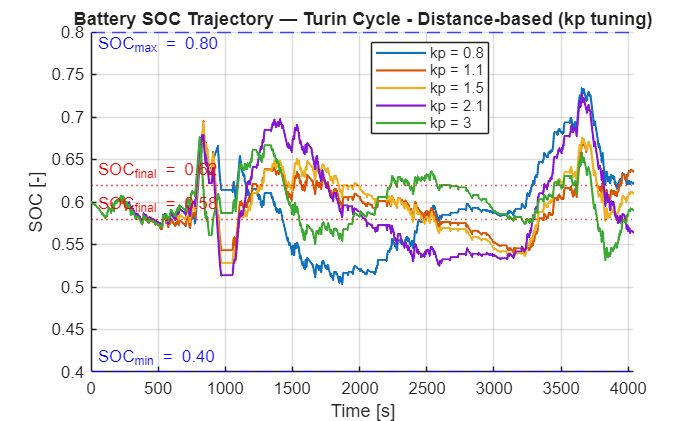


time_Tur_dist = Turin.time_s;
time_Tur_dist(end+1) = time_Tur_dist(end) + 1;    % a simply modification for the plot, nothing change.

%% Plot 1: SOC trajectories for all kp values
figure('Name','Turin cycle - SOC vs kp','NumberTitle','off')
hold on
legend_entries = cell(N,1);
for i = 1:N
    plot(time_Tur_dist, SOC_sim_dist_Tur_all{i}, 'Color', colors(i,:), 'LineWidth', 1.3);
    legend_entries{i} = sprintf('kp = %g', kp_dist_vec(i));
end
yline(0.40, 'b--', 'SOC_{min} = 0.40', 'LabelHorizontalAlignment','left')
yline(0.80, 'b--', 'SOC_{max} = 0.80', 'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom')
yline(0.62, 'r:',  'SOC_{final} = 0.62', 'LabelHorizontalAlignment','left')
yline(0.58, 'r:',  'SOC_{final} = 0.58', 'LabelHorizontalAlignment','left')
xlabel('Time [s]')
ylabel('SOC [-]')
title('Battery SOC Trajectory — Turin Cycle - Distance-based (kp tuning)')
legend(legend_entries, 'Location','best')
xlim([0 length(time_Tur_dist)])
grid on
hold off

This figure overlays the SOC trajectories of the five tuning simulations on the Turin cycle for $k_p \in \{0.8, 1.1, 1.5, 2.1, 3\}$. The Turin cycle lasts approximately 4000 s and features a mixed profile (urban + rural + highway), making it highly representative of a real-world driving mission.

- $k_p = 0.8$**:** Very low gain; the correction on s is slow and insufficient. The SOC progressively drifts away from the target: after remaining relatively high for most of the mission, it experiences a sharp upward overshoot near t = 3700 s, finishing at a final SOC ( $SOC_{final}$ ) of $\approx 0.69$ . This value is clearly outside the $[0.58, 0.62]$ charge-sustaining band, as the controller behaves almost like a fixed-factor ECMS.

- $k_p = 1.1$**:** Displays very wide and unstable excursions. The SOC drops heavily to a minimum of $\approx 0.46$ around t = 1600 s before recovering. At the end of the cycle, it drops again, settling around $0.56$ , which fails to meet the lower boundary of the final target band.

- $k_p = 1.5$**:** Displays moderate oscillations throughout the cycle, with $SOC_{final} \approx 0.61$. It perfectly satisfies the final charge-sustaining criterion and shows the lowest percentage variation of the s profile among the valid candidates, making it the optimal selection for the distance-based controller.

- $k_p = 2.1$**:** Shows a structurally similar tracking behavior to the optimal candidate, concluding with $SOC_{final} \approx 0.60$. However, it exhibits more pronounced transient excursions, particularly during the sharp peak at t = 800 s.

- $k_p = 3$**:** Features highly aggressive and severe SOC oscillations across the entire cycle (dropping down to $\approx 0.51$ at t = 1000 s and immediately spiking up to $\approx 0.74$ at t = 1350 s). While it technically manages to land within the final target band ( $SOC_{final} \approx 0.615$ ), its highly erratic intra-cycle behavior indicates a controller close to limit-cycling due to overcorrection.

The [0.58, 0.62] charge-sustaining band is indicated by the red dotted lines; the physical safety limits [0.40, 0.80] are never breached by any of the tested $k_p$ values.

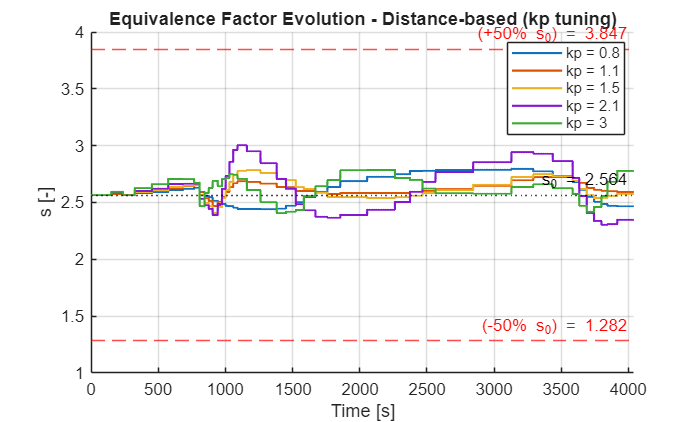


%% Plot 2: s evolution for all kp values
time_Tur_dist_s = time_Tur_dist;
time_Tur_dist_s(end) = [];

figure('Name','s evolution vs kp','NumberTitle','off')
hold on
for i = 1:N
    plot(time_Tur_dist_s, s_array_dist_Tur_all{i}, 'Color', colors(i,:), 'LineWidth', 1.3);
end
yline(s_lower, 'r--', sprintf('(-50%% s_0) = %.3f', s_lower));
yline(s_upper, 'r--', sprintf('(+50%% s_0) = %.3f', s_upper));
yline(s_0,     'k:',  sprintf('s_0 = %.3f', s_0));
xlabel('Time [s]')
ylabel('s [-]')
title('Equivalence Factor Evolution - Distance-based (kp tuning)')
legend(legend_entries, 'Location','best')
xlim([0 length(time_Tur_dist_s)])
grid on
hold off

This chart tracks the evolution of the equivalence factor $s$ over the Turin cycle for the same five $k_p$ values. The $\pm50\%$ boundaries relative to $s_0 = 2.564$ are [1.282, 3.847]. All profiles start at s_0 = 2.564 and never breach the safety bounds; therefore, saturation on s is never triggered during this cycle.

Due to the spatial discrete-step update law ( $d_{update} = 1000$ m), all curves exhibit a characteristic stepped behavior rather than a continuous smooth path.

- $k_p = 0.8$**:** $s$ varies slowly and falls behind the actual energy demand of the cycle. In the final segment (after t = 3000 s), instead of increasing to lower the battery charge, it remains too low ( $\approx 2.45$ ), explaining why the SOC experiences a final uncontrolled upward drift.

- $k_p = 1.1$**:** Shows deep and delayed excursions, dropping heavily to a minimum of $\approx 2.30$ around t = 1100 s to react to the initial SOC peak. This delayed, low value of s keeps the combustion engine off for too long, justifying the subsequent massive drop in SOC.

- $k_p = 1.5$**:** Tightly bounded variation centered around $s_0$. It stays within a narrow and well-damped range (between $\approx 2.50$ and $\approx 2.80$). This is the smoothest profile among the valid candidates, confirming the selection based on minimizing the percentage variation of s.

- $k_p = 2.1$**:** Similar to 1.5 but with visibly wider and more sudden stepped excursions, tracking the target with higher transient effort.

- $k_p = 3$**:** Exhibits the widest and most severe excursions in s, spiking rapidly up to $\approx 3.15$ at t = 1100 s and down to $\approx 2.15$ at t = 1650 s. The controller is over-reactive: minor transient SOC deviations trigger massive corrections in s, introducing unwanted aggression into the powertrain strategy.

fprintf('\n--- kp tuning summary ---\n');


--- kp tuning summary ---


% % Summary kp-table % %
T_dist_results = table(kp_dist_vec(:), SOC_final_dist_all, final_ok, SOC_min_dist_all, SOC_max_dist_all, bounds_ok, s_final_dist_all, s_var_perc_dist_all, value_s_final_ok, ...
'VariableNames', {'kp_dist','SOC_final','Final_OK','SOC_min','SOC_max','Bounds_OK', 's_final', 's_percent', 'value_s_OK'});
disp(T_dist_results)

    kp_dist    SOC_final    Final_OK    SOC_min    SOC_max    Bounds_OK    s_final    s_percent    value_s_OK
    _______    _________    ________    _______    _______    _________    _______    _________    __________

      0.8       0.62082      false      0.50321    0.73366      true       2.4651      13.939        true    
      1.1       0.63499      false      0.53977    0.69518      true       2.5925      9.9077        true    
      1.5       0.60915      true       0.52854    0.69386      true       2.5768      14.678        true    
      2.1       0.56348      false      0.51347    0.72721      true       2.3487      27.226        true    
        3       0.58946      true


%% --- OPTIMIZATION SEARCH (Distance-Based) ---

% Find the original indices that satisfy all validity criteria
valid_idx_dist = find(final_ok);

if isempty(valid_idx_dist)
    % Fallback: If no candidate satisfies all criteria, pick the one with SOC closest to 0.60
    [~, idx_d_opt] = min(abs(SOC_final_dist_all - 0.60));
else
    % Extract the 's' variation percentage only for the valid candidates
    value_s_percent_dist = s_var_perc_dist_all(valid_idx_dist);
    
    % Search for the minimum 's' variation among them
    [~, idx_d_ideal] = min(value_s_percent_dist);
    
    % Trace back to the absolute original index to avoid array mismatch
    idx_d_opt = valid_idx_dist(idx_d_ideal);
end

% Extract the final optimal values
kp_dist_opt = kp_dist_vec(idx_d_opt);            % evaluation of optimal kp for distance-based 


fprintf('\n--- The optimal kp (Distance-Based) found is: %g (SOC final = %.4f)  ---\n', kp_dist_opt, SOC_final_dist_all(idx_d_opt));


--- The optimal kp (Distance-Based) found is: 1.5 (SOC final = 0.6092)  ---


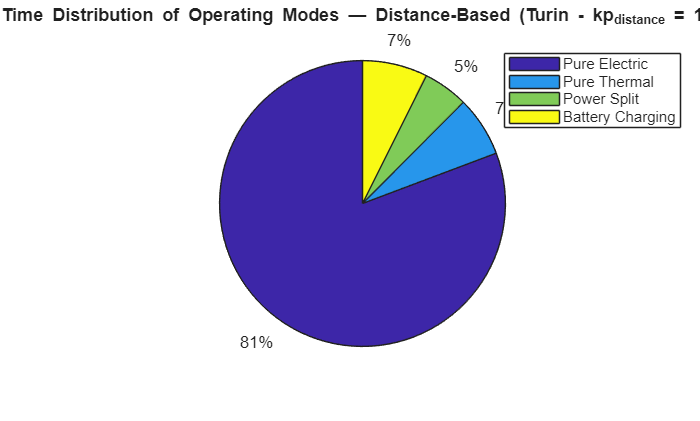

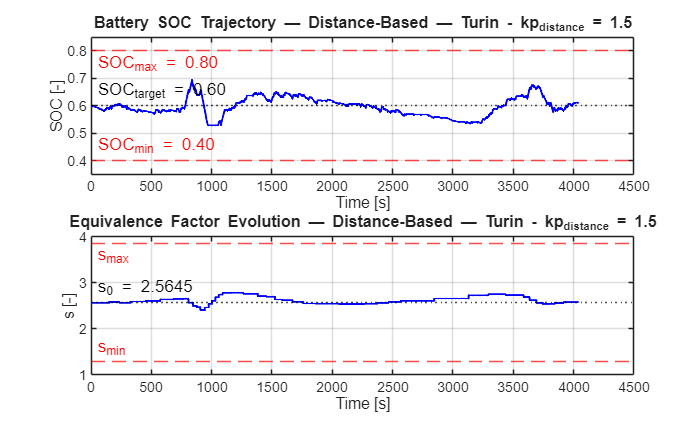


label = sprintf('Turin - kp_{distance} = %g', kp_dist_opt);
[SOC_sim_dist_T, s_array_dist_T, prof_dist_T, mf_eq_dist_T, dc_T, Results_Tur_dist] = simLoopDistance(Turin, s_0, kp_dist_opt, d_update, veh, label,0);

About the pie chart, the results for Turin cycle (Distance-based) are the same of Time-based.

The figure below displays the time-domain evolution of the SOC and the equivalence factor (s) for the **distance-based** variant on the Turin cycle, using the optimal gain $kp_{distance}$ = 1.5.

Compared to the time-based approach, this variant exhibits slightly more pronounced dynamics during the initial phase of the cycle. The SOC drops to roughly 0.55 within the first 700 s, followed by a sharp recovery that peaks at ~0.70 near 800 s, before stabilizing around **0.61** in the second half. Correspondingly, the equivalence factor s behaves in a more stepped and dynamic manner: it initially climbs to compensate for the early SOC drop, then sharply drops to ~2.45 immediately after the SOC peak, and finally settles near 2.6.

disp(Results_Tur_dist)

                 Cycle                 Fuel Consumption (kg)    Fuel Economy (l/100km)    SOC_final    s_final
    _______________________________    _____________________    ______________________    _________    _______

    {'Turin - kp_{distance} = 1.5'}           1.4977                    4.4367             0.60915     2.5768 



The table summarizes the cycle-wide performance of the distance-based A-ECMS on the Turin cycle using $kp_{distance} = 1.5$.

The controller achieves a `Fuel Economy of 4.44 l/100km`. This is slightly less efficient than the time-based variant. However, it achieves a `final SOC of 0.609`, which is mathematically closer to the 0.60 target, while the `final equivalence factor (2.58)` remains stable and safely bounded.

This minor drop in fuel efficiency is a direct consequence of the spatial update trigger. During the slow urban segments of the Turin cycle, covering 1 km takes significantly longer than 60 seconds. This lower update frequency allows larger transient SOC errors to accumulate. To successfully recover this error and enforce a tighter final SOC, the controller must execute more pronounced corrections to s, briefly forcing the engine into less optimal operating regions.

Ultimately, these results highlight the trade-off of the distance-based approach: it delivers improved final charge-sustaining accuracy at the cost of a marginal fuel penalty, confirming $kp_{distance} = 1.5$ as a robust and highly effective compromise.

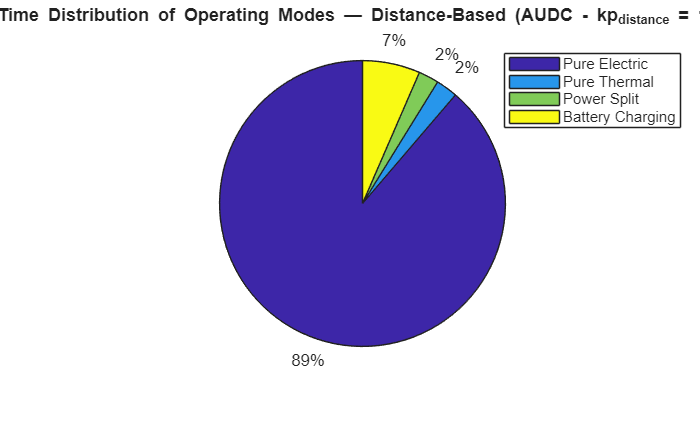

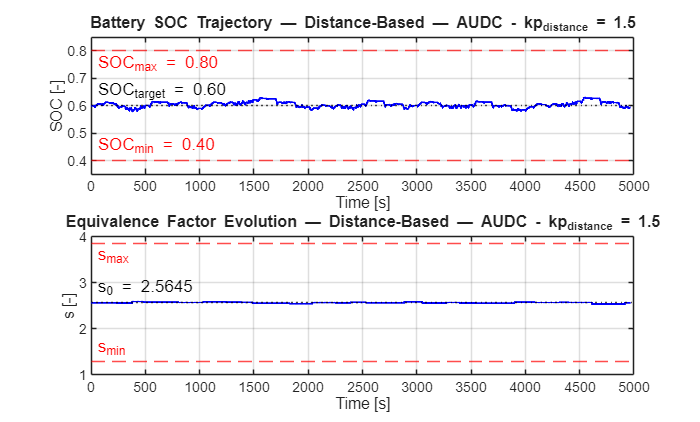

% % % Urban validation % % %
label = sprintf('AUDC - kp_{distance} = %g', kp_dist_opt);
[SOC_sim_dist_Urb, s_array_dist_Urb, prof_dist_Urb, mf_eq_dist_Urb, dc_Urban, Results_Urban_dist] = simLoopDistance(AUDC_5x, s_0, kp_dist_opt, d_update,veh,label,0);

The pie chart is nearly identical to the time-based version. In an urban environment, both controllers yield virtually the same modal split because low power demand heavily favors EV mode, regardless of how often *s* is updated.

The SOC stays remarkably tightly bound around 0.60 for the entire duration (~5000 s), with fluctuations kept under ±0.03. The equivalence factor *s* remains nearly flat, showing minute steps at each update interval.

This highly stable behavior comes down to the physics of the trigger: in the AUDC, the average speed is low (~20–30 km/h), meaning a 1 km distance interval translates to several minutes of driving. The distance-based controller updates *s* much less frequently than the time-based one, but since urban SOC deviations are inherently small, rare updates are entirely adequate and deliver a smoother trajectory.

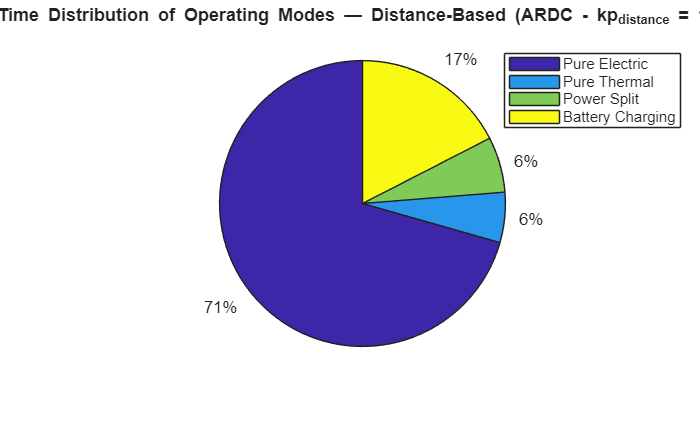

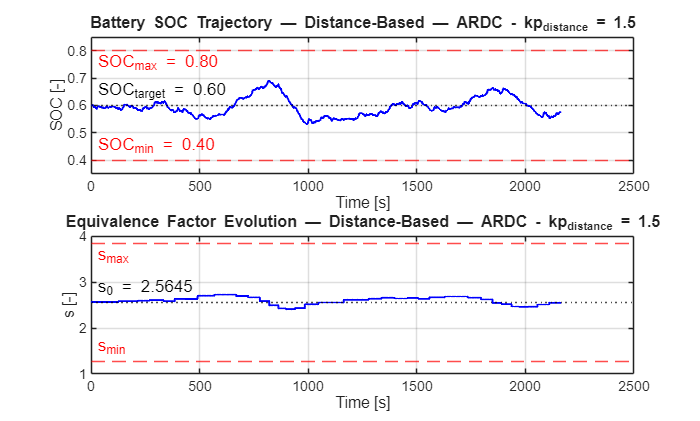

% % % Rural validation % % %
label = sprintf('ARDC - kp_{distance} = %g', kp_dist_opt);
[SOC_sim_dist_Rur, s_array_dist_Rur, prof_dist_Rur, mf_eq_dist_Rur, dc_Rural, Results_Rural_dist] = simLoopDistance(ARDC_2x, s_0, kp_dist_opt, d_update,veh,label,0);

The distance-based ARDC pie chart  is almost identical to the time-based one. The rural cycle's average speed is high enough to make the 1 km spatial trigger comparable to the 60 s temporal trigger (~130 s per km at an average of ~28 km/h). Consequently, both versions behave analogously. The SOC profile shows fluctuations between ~0.56 and ~0.65, closely matching the time-based. Charge-sustaining criteria are fully met.

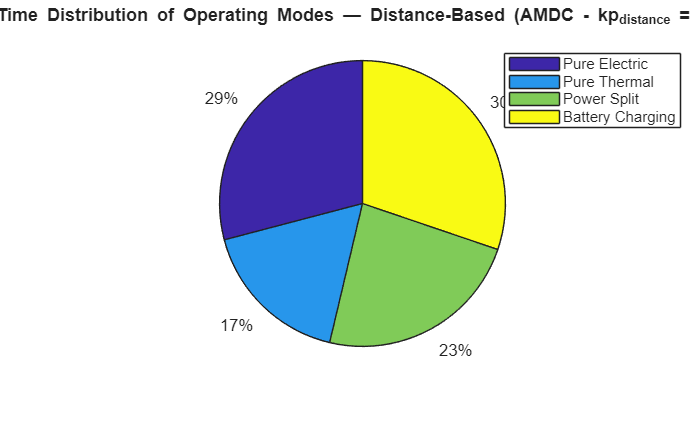

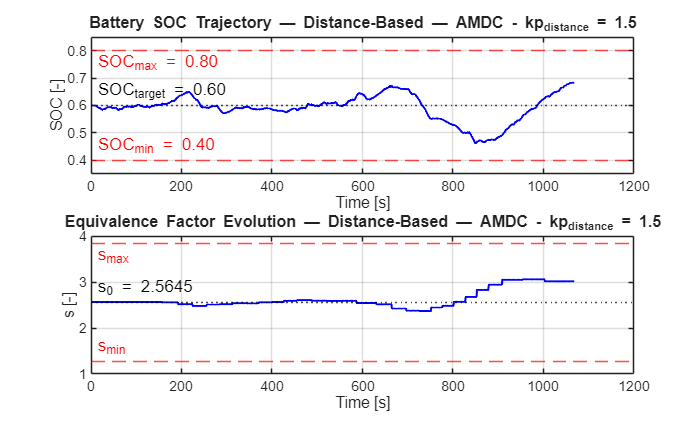

% % % Motorway validation % % %
label = sprintf('AMDC - kp_{distance} = %g', kp_dist_opt);
[SOC_sim_dist_Mot, s_array_dist_Mot, prof_dist_Mot, mf_eq_dist_Mot, dc_Mot, Results_Mot_dist] = simLoopDistance(AMDC, s_0, kp_dist_opt, d_update,veh,label,0);

The pie chart split is virtually identical to the time-based version. The SOC and s profile reveals the same failure pattern: a dip to ~0.46 around t = 850 s, followed by a final overshootup to ~0.68. The final SOC for the distance-based variant is also significantly outside the target band on the AMDC.

Paradoxically, on the highway, the distance-based trigger fires more frequently: at 120 km/h, 1 km takes only 30 s, meaning the controller updates twice as fast as the 60-second time-based mode. Despite this, the correction falls short. This proves that the core issue is not the update frequency, but rather the inadequacy of using a single kp value calibrated on a mixed cycle to manage a sustained, high-power driving profile.

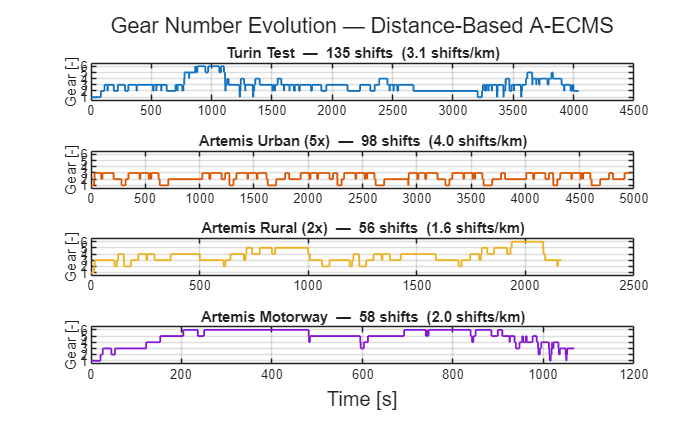

%% Gear profile — all four cycles (distance-based A-ECMS)
gears    = {prof_dist_T.vehPrf.gearNumber, prof_dist_Urb.vehPrf.gearNumber, ...
            prof_dist_Rur.vehPrf.gearNumber, prof_dist_Mot.vehPrf.gearNumber};
missions = {Turin, AUDC_5x, ARDC_2x, AMDC};
names    = {'Turin Test', 'Artemis Urban (5x)', 'Artemis Rural (2x)', 'Artemis Motorway'};
cols     = lines(4);

figure('Name','Gear profile - Distance-based cycles','NumberTitle','off')
tg = tiledlayout(4,1);

for i = 1:4
    g  = gears{i};
    t  = missions{i}.time_s;
    d  = trapz(t, missions{i}.speed_km_h/3.6) / 1000;   % distance [km]
    nS = sum(diff(g) ~= 0);                             % n° of shifts

    nexttile
    stairs(t, g, 'LineWidth', 1.1, 'Color', cols(i,:))
    grid on, box on
    ylim([0.5 6.5]); yticks(1:6); ylabel('Gear [-]')
    title(sprintf('%s  —  %d shifts  (%.1f shifts/km)', names{i}, nS, nS/d))
end
xlabel(tg, 'Time [s]')
title(tg, 'Gear Number Evolution — Distance-Based A-ECMS')



% % Summary table % %
fprintf('\n--- Artemis Cycles'' Results  summary ---\n');


--- Artemis Cycles' Results  summary ---


T_dist_all = [Results_Urban_dist; Results_Rural_dist; Results_Mot_dist];
disp(T_dist_all)

                Cycle                 Fuel Consumption (kg)    Fuel Economy (l/100km)    SOC_final    s_final
    ______________________________    _____________________    ______________________    _________    _______

    {'AUDC - kp_{distance} = 1.5'}           0.77236                   4.0408             0.59412     2.5651 
    {'ARDC - kp_{distance} = 1.5'}            1.0988                   4.0521             0.57545     2.5496 
    {'AMDC - kp_{distance} = 1.5'}            1.6206                   6.9875             0.68337     3.0146 



**Gear-shifting behaviour.** The gear-number trajectories of the distance-based variant are virtually identical to the time-based ones, since the gear is selected by the same ECMS minimisation at every step and only the s-update trigger differs. The same cycle ranking holds: the Urban cycle shows the highest shifting activity and the Motorway cycle the lowest.

The results obtained with the distance-based variant are practically identical to the time-based approach. Therefore, the `Urban cycle (AUDC)` is the absolute best performer, as same as the time-based, exhibiting extremely linear and flat trajectories for both the SOC and the equivalence factor ( $s$ ), yielding an excellent `fuel economy of 4.04 l/100km`. For the other cycles (Rural and Motorway), the overall performance and inherent limitations remain virtually unchanged.

## Analysis and Discussion (DIstance-Based)

- Was tuning $k_p
$  easier for this variant?

The tuning execution was not "easier", as the underlying methodology and multi-criteria optimization script remained identical. However, finding an optimal value was noticeably faster and more robust. During the grid search, the distance-based formulation proved to be more forgiving: a wider range of $k_p$ candidates successfully satisfied all the strict validity criteria (charge-sustaining final SOC, physical battery bounds, and bounded s) compared to the time-based variant. For instance, even at very high $k_p$ values (such as 18 or 19), the final SOC condition was technically respected; however, the controller became explicitly too aggressive, rendering it a non-ideal solution, so these values are not presented in the main script. Therefore, from this larger pool of valid candidates, $kp_{distance} = 1.5$ was selected because it delivered the smoothest and most stable trajectories for both the SOC and the equivalence factor, effectively minimizing any erratic oscillations.

- Does this distance-based variant solve some of the drawbacks of the time-based version?

Yes, it fundamentally resolves the critical issue of idle updating. The primary drawback of the time-based version is its reliance on a rigid chronological clock ( $T_{update} = 60$ s). If the vehicle is stopped at a traffic light or caught in a traffic jam, the time counter keeps ticking and eventually triggers an update to the equivalence factor $s$, even though no actual driving or significant energy consumption has occurred. This blind chronological trigger can lead to spurious, unnecessary, and potentially destabilizing corrections to the SOC strategy.

Conversely, the distance-based variant ( $d_{update} = 1000$ m) intrinsically links the update trigger to the actual physical work done by the vehicle. When the vehicle is stopped, the distance counter naturally pauses. This ensures that the equivalence factor is only adjusted in response to actual energy consumption and distance covered, making the distance-based control strategy much more realistic, physically meaningful, and resilient to different traffic conditions.

## Main loop function Time-Based

The simLoop function executes a complete time-based A-ECMS simulation over an arbitrary driving cycle. It receives, as input, the mission struct (speed, acceleration, time), the controller parameters (*s_0, kp, T_update*), the vehicle data ( $veh$ ), a string label used in figure titles ( *label* ) and a *no_fig* flag that disables both figure generation (used during kp tuning to keep the sweep silent and fast). As ouput, it receives the battery State of Charge array ( *SOC_sim* ), the equivalence factor array ( *s_array* ), powertrain operating profiles (engine, electric machine, battery, vehicle) ( *prof* ), the equivalent fuel consumption array ( *mf_eq* ), a summary table containing cycle name, fuel consumption, fuel economy, final SOC, and final equivalence factor ( *T_results* ) and the handle to the generated SOC & $s$ trajectory plot ( *image* ).

**Algorithm:**

- **Preallocation:** Initializes the state and control arrays (SOC_sim, s_array, $\gamma$ / $\alpha$  arrays, mf_eq) with the proper +1 sizing for the states.

- **Initialization:** Sets the controller state (s_n = s_prev = s_0, tc = 1, gamma_prev = 1, SOC_sim(1) = 0.6). This specific initialization of `tc` ensures that the equivalence factor $s$ is updated precisely every 60 seconds, as the trigger condition tc >= T_update inside the controller aligns perfectly with the 1 Hz discrete simulation sampling time ( $dt = 1$ s). Additionally, the variable `gamma_prev = 1` is explicitly set to define the first gear as the starting condition, ensuring that the driving cycle always begins from the first gear. This state is then dynamically updated at the end of each iteration to smoothly track the optimal gear sequence selected by the controller. The warning flag inside the controller is linked to no_fig so that warnings remain silent during tuning.

- **Main Loop:** Iterates over the cycle samples. At each step, it calls A_ECMS_controller to obtain the optimal controls (gamma_opt, alpha_opt, mf_opt) and the updated controller state. Then, it calls hev_cell_model to advance the SOC and collect the powertrain profiles.

- **Data Packing:** Converts the non-scalar engPrf, emPrf, battPrf,  vehPrf cell arrays into scalar structs via `structArray2struct` and packs them into prof for post-processing.

- **Graphics:** If no_fig == 0, it generates the full plot suite: a pie chart for operating modes, and the custom SOC/s trajectory plot and power profiles.

- **Performance Metrics:** Computes cycle-wide metrics like total fuel consumption (kg) and fuel economy (l/100km) via trapezoidal integration (trapz) of fuel flow rate and vehicle speed. These metrics are returned as a 1-row table (T_results) to be collected by the main script.

Finally, the figure handle `image` is always initialized to an empty array ([ ]) before the if no_fig == 0 block. This guarantees that the function can return its full 6-output signature even during silent tuning runs without triggering a runtime error for an unassigned variable.

% --- MAIN SIMULATION LOOP TIME-BASED ---
function [SOC_sim, s_array, prof, mf_eq, T_results, image] = simLoop(mission, s_0, kp, T_update, veh, label, no_fig)

% SIMLOOP
% Executes a complete time-based A-ECMS simulation over a given driving cycle.
%
% INPUT Arguments:
%   mission  : struct - driving cycle data (speed, acceleration, time)
%   s_0      : double - initial calibrated equivalence factor [-]
%   kp       : double - proportional gain for the A-ECMS update law
%   T_update : double - time interval for the equivalence factor update [s]
%   veh      : struct - vehicle data structure
%   label    : string/char - name of the cycle used for plots and tables
%   no_fig   : double - logical flag (0 = plot figures, 1 = suppress figures and warnings)
%
% OUTPUT Arguments:
%   SOC_sim   : array  - battery State of Charge trajectory [-]
%   s_array   : array  - equivalence factor trajectory [-]
%   prof      : struct - powertrain operating profiles (engine, EM, battery, vehicle)
%   mf_eq     : array  - equivalent fuel consumption trajectory [g/s]
%   T_results : table  - summary results (Fuel Consumption, Economy, Final SOC, Final s)
%   image     : figure - handle to the generated SOC & s trajectory plot (empty if no_fig == 1)


% % For cell inputs
if iscell(label)
    cycleName = char(label{1});
else
    cycleName = char(label);
end

vehSpd = mission.speed_km_h ./ 3.6;         % vehicle speed in (m/s)
vehAcc = mission.acceleration_m_s2;         % vehicle acceleration in (m/s^2)
time = mission.time_s;                      % mission time in (s)

% Preallocation arrays
SOC_sim = zeros(length(time) + 1, 1);
gamma_opt_array = zeros(length(time), 1);
alpha_opt_array = zeros(length(time), 1);
mf_eq = zeros(length(time), 1);
s_array = zeros(length(time), 1); 

% Initialize the controller state
s_n = s_0;
s_prev = s_0;
tc = 1;

gamma_prev = 1;     % Initialize in first gear, update at each step 

% Initialize the simulation parameters
controller = 1;                          % Activate controller to raise warnings
SOC_sim(1) = 0.6;                        % Initial battery state of charge ( 60% )

% Main loop
for n = 1:length(time)

    s_array(n) = s_n;

    % Get the optimal gamma and alpha values from ECMS_controller
    [gamma_opt,alpha_opt,mf_opt, s_n, s_prev, tc] = A_ECMS_controller(vehAcc(n), vehSpd(n), SOC_sim(n), veh, s_n, s_prev, tc, kp, T_update, gamma_prev, controller);

    [x_next, ~, ~, engPrf(n), emPrf(n), battPrf(n),vehPrf(n)] = hev_cell_model({SOC_sim(n)}, {gamma_opt,alpha_opt}, {vehSpd(n),vehAcc(n)}, veh); 
    
    % Update state of charge
    SOC_sim(n+1) = x_next{1};

    mf_eq(n) = mf_opt;

    % Update the gear 
    gamma_prev = gamma_opt;

    % Store the optimal gear number and torque-split factor for post-processing analysis
    gamma_opt_array(n) = gamma_opt;
    alpha_opt_array(n) = alpha_opt;
end

% Transform the non-scalar struct containing time profiles into scalar
% structs; this makes their manipulation easier.
engPrf = structArray2struct(engPrf);
emPrf = structArray2struct(emPrf);
battPrf = structArray2struct(battPrf);
vehPrf = structArray2struct(vehPrf);

% Pack profiles into a single structure
prof.engPrf = engPrf;
prof.emPrf = emPrf;
prof.battPrf = battPrf;
prof.vehPrf = vehPrf;

image = [];

if no_fig == 0          % I don't want figures : 1 = TRUE,  I want figures : 0 = FALSE

    % EXTRA PLOT 1: Operating Modes Distribution
    % Calculate the time spent in each operating mode by analyzing the 'engAlpha' array
    % Count the number of seconds for each condition
    time_PE = sum(alpha_opt_array == 0); % Pure Electric: alpha is exactly 0
    time_PT = sum(alpha_opt_array == 1); % Pure Thermal: alpha is exactly 1
    time_PS = sum(alpha_opt_array > 0 & alpha_opt_array < 1); % Power Split: alpha is between 0 and 1
    time_BC = sum(alpha_opt_array > 1); % Battery Charging: alpha is strictly greater than 1

    % Create the Pie Chart
    figure('Name','Operating Modes Distribution','NumberTitle','off')
    labels = {'Pure Electric', 'Pure Thermal', 'Power Split', 'Battery Charging'};
    % The pie function automatically calculates the percentages based on the given array
    pie([time_PE, time_PT, time_PS, time_BC]);
    legend(labels, "Position", [0.7199 0.6955 0.2525, 0.1779])
    title(sprintf('Time Distribution of Operating Modes — Time-Based (%s)',cycleName))

    % EXTRA PLOT 2: SOC trajectory & Equivalence Factor trajectory
    time = mission.time_s;
    image = figure('Name','SOC & s trajectories','NumberTitle','off');
    hold on, box on
    subplot(2,1,1)
    plot(time, SOC_sim(1:end-1), 'b', 'LineWidth', 1.2)
    yline(0.40, 'r--', 'SOC_{min} = 0.40', 'LabelHorizontalAlignment','left')
    yline(0.80, 'r--', 'SOC_{max} = 0.80', 'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom')
    yline(0.6, 'k:', 'SOC_{target} = 0.60', 'LabelHorizontalAlignment','left')
    xlabel('Time [s]')
    ylabel('SOC [-]')
    ylim([0.35 0.85])
    title(sprintf('Battery SOC Trajectory — Time-Based — %s', cycleName))
    grid on

    subplot(2,1,2)
    plot(time, s_array, 'b', 'LineWidth', 1.2)
    yline(s_0 - 0.5*s_0, 'r--', 's_{min}', 'LabelHorizontalAlignment','left')
    yline(s_0 + 0.5*s_0, 'r--', 's_{max}', 'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom')
    yline(s_0, 'k:', 's_{0} = 2.5645', 'LabelHorizontalAlignment','left')
    xlabel('Time [s]')
    ylabel('s [-]')
    title(sprintf('Equivalence Factor Evolution — Time-Based — %s', cycleName))
    grid on

    % Plot power profiles to inspect the 4 operating conditions
    powerProfiles(prof);
end

% 1. Calculate total fuel consumption in kg
fuelConsumption = trapz(time,engPrf.fuelFlwRate)/1000; 

% 2. Calculate TOTAL distance in km 
distance = trapz(time, vehSpd) / 1000; 

% 3. Calculate total fuel volume in liters
fuel_volume = fuelConsumption / veh.eng.fuelDensity;

% 4. Calculate fuel economy in l/100km
fuelEconomy = (fuel_volume / distance) * 100; 

% 5. Get final state of charge
finalSOC = SOC_sim(end); 

% 6. Get the final equivalence factor s
s_final = s_array(end);

%% Summary table
T_results = table({cycleName},fuelConsumption, fuelEconomy, finalSOC, s_final, ...
    'VariableNames', {'Cycle','Fuel Consumption (kg)','Fuel Economy (l/100km)','SOC_final', 's_final'});
end

## Main loop function Distance-Based

The simLoopDistance function has the same structure as simLoop but maintains a distance counter dc instead of a time counter tc. The input of the function are the same of simLoop function instead of `d_update`, the distance interval threshold for the equivalence factor update ( in meters ). As output, the difference from Time-based function is `dc_array`, a trajectory tracking the accumulated distance counter ( in meters ). 

**Algorithm: **

 All the internals (including variable initialization, the vectorized plot suite, and the trapezoidal integration for performance-metric computation) are identical to `simLoop`, so the same algorithmic steps apply.

The only structural difference is the trigger condition: the counter is incremented by the physical distance covered in that step (`vehSpd * veh.dt`), and the equivalence factor is evaluated whenever `dc` exceeds `d_update`. From a user-facing perspective, the update parameter unit shifts from time to space: `d_update` is provided in meters ( 1000 m ) rather than in seconds. Power profile plots are not shown since they don't provide any noteworthy difference with respect to time based ones. 

% --- MAIN SIMULATION LOOP DISTANCE-BASED ---
function [SOC_sim, s_array, prof, mf_eq, dc_array, T_results, image] = simLoopDistance(mission, s_0, kp, d_update, veh, cycle, no_fig)

% SIMLOOPDISTANCE
% Executes a complete distance-based A-ECMS simulation over a given driving cycle.
%
% INPUT Arguments:
%   mission  : struct - driving cycle data (speed, acceleration, time)
%   s_0      : double - initial calibrated equivalence factor [-]
%   kp       : double - proportional gain for the A-ECMS update law
%   d_update : double - distance interval for the equivalence factor update [m]
%   veh      : struct - vehicle data structure
%   cycle    : string/char - name of the cycle used for plots and tables
%   no_fig   : double - logical flag (0 = plot figures, 1 = suppress figures and warnings)
%
% OUTPUT Arguments:
%   SOC_sim   : array  - battery State of Charge trajectory [-]
%   s_array   : array  - equivalence factor trajectory [-]
%   prof      : struct - powertrain operating profiles (engine, EM, battery, vehicle)
%   mf_eq     : array  - equivalent fuel consumption trajectory [g/s]
%   dc_array  : array  - distance counter trajectory tracking the traveled meters [m]
%   T_results : table  - summary results (Fuel Consumption, Economy, Final SOC, Final s)
%   image     : figure - handle to the generated SOC & s trajectory plot (empty if no_fig == 1)


% For cell inputs
if iscell(cycle)
    cycleName = char(cycle{1});
else
    cycleName = char(cycle);
end

vehSpd = mission.speed_km_h ./ 3.6;         % vehicle speed in (m/s)
vehAcc = mission.acceleration_m_s2;         % vehicle acceleration in (m/s^2)
time = mission.time_s;                      % mission time in (s)

% Preallocation arrays
SOC_sim = zeros(length(time) + 1, 1);
gamma_opt_array = zeros(length(time), 1);
alpha_opt_array = zeros(length(time), 1);
mf_eq = zeros(length(time), 1);
s_array = zeros(length(time), 1); 
dc_array = zeros(length(time), 1);

% Initialize the controller state
s_n = s_0;
s_prev = s_0;
dc = 0;

gamma_prev = 1;     % Initialize in first gear, update at each step 

% Initialize the simulation parameters
controller = 1;                          % Activate controller to raise warnings
SOC_sim(1) = 0.6;                        % Initial battery state of charge ( 60% )

% Main loop
for n = 1:length(time)   

    s_array(n) = s_n;

    dc_array(n) = dc;         % distance-counter

    % Get the optimal gamma and alpha values from ECMS_controller
    [gamma_opt,alpha_opt,mf_opt, s_n, s_prev, dc] = Km_A_ECMS_controller(vehAcc(n), vehSpd(n), SOC_sim(n), veh, s_n, s_prev, dc, kp, d_update, gamma_prev, controller);

    [x_next, ~, ~, engPrf(n), emPrf(n), battPrf(n),vehPrf(n)] = hev_cell_model({SOC_sim(n)}, {gamma_opt,alpha_opt}, {vehSpd(n),vehAcc(n)}, veh); 

    % Update state of charge
    SOC_sim(n+1) = x_next{1};

    mf_eq(n) = mf_opt; 

    % Update the gear 
    gamma_prev = gamma_opt;

    % Store the optimal gear number and torque-split factor for post-processing analysis
    gamma_opt_array(n) = gamma_opt;
    alpha_opt_array(n) = alpha_opt;
end

% Transform the non-scalar struct containing time profiles into scalar
% structs; this makes their manipulation easier.
engPrf = structArray2struct(engPrf);
emPrf = structArray2struct(emPrf);
battPrf = structArray2struct(battPrf);
vehPrf = structArray2struct(vehPrf);

% Pack profiles into a single structure
prof.engPrf = engPrf;
prof.emPrf = emPrf;
prof.battPrf = battPrf;
prof.vehPrf = vehPrf;

image = [];

if no_fig == 0     % I don't want figures : 1 = TRUE,  I want figures : 0 = FALSE

    % EXTRA PLOT 1: Operating Modes Distribution
    % Calculate the time spent in each operating mode by analyzing the 'engAlpha' array
    % Count the number of seconds for each condition
    time_PE = sum(alpha_opt_array == 0); % Pure Electric: alpha is exactly 0
    time_PT = sum(alpha_opt_array == 1); % Pure Thermal: alpha is exactly 1
    time_PS = sum(alpha_opt_array > 0 & alpha_opt_array < 1); % Power Split: alpha is between 0 and 1
    time_BC = sum(alpha_opt_array > 1); % Battery Charging: alpha is strictly greater than 1

    % Create the Pie Chart
    figure('Name','Operating Modes Distribution','NumberTitle','off')
    labels = {'Pure Electric', 'Pure Thermal', 'Power Split', 'Battery Charging'};
    % The pie function automatically calculates the percentages based on the given array
    pie([time_PE, time_PT, time_PS, time_BC]);
    legend(labels, "Position", [0.7199 0.6955 0.2525, 0.1779])
    title(sprintf('Time Distribution of Operating Modes — Distance-Based (%s)',cycleName))

    % EXTRA PLOT 2: SOC trajectory & Equivalence Factor trajectory
    time = mission.time_s;
    image = figure('Name','SOC & s trajectories','NumberTitle','off');
    hold on, box on
    subplot(2,1,1)
    plot(time, SOC_sim(1:end-1), 'b', 'LineWidth', 1.2)
    yline(0.40, 'r--', 'SOC_{min} = 0.40', 'LabelHorizontalAlignment','left')
    yline(0.80, 'r--', 'SOC_{max} = 0.80', 'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom')
    yline(0.6, 'k:', 'SOC_{target} = 0.60', 'LabelHorizontalAlignment','left')
    xlabel('Time [s]')
    ylabel('SOC [-]')
    ylim([0.35 0.85])
    title(sprintf('Battery SOC Trajectory — Distance-Based — %s', cycleName))
    grid on

    subplot(2,1,2)
    plot(time, s_array, 'b', 'LineWidth', 1.2)
    yline(s_0 - 0.5*s_0, 'r--', 's_{min}', 'LabelHorizontalAlignment','left')
    yline(s_0 + 0.5*s_0, 'r--', 's_{max}', 'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom')
    yline(s_0, 'k:', 's_{0} = 2.5645', 'LabelHorizontalAlignment','left')
    xlabel('Time [s]')
    ylabel('s [-]')
    title(sprintf('Equivalence Factor Evolution — Distance-Based — %s', cycleName))
    grid on
end

% 1. Calculate total fuel consumption in kg
fuelConsumption = trapz(time,engPrf.fuelFlwRate)/1000; 

% 2. Calculate TOTAL distance in km 
distance = trapz(time, vehSpd) / 1000; 

% 3. Calculate total fuel volume in liters
fuel_volume = fuelConsumption / veh.eng.fuelDensity;

% 4. Calculate fuel economy in l/100km
fuelEconomy = (fuel_volume / distance) * 100; 

% 5. Get final state of charge
finalSOC = SOC_sim(end); 

% 6. Get the final equivalence factor s
s_final = s_array(end);

%% Summary table
T_results = table({cycleName},fuelConsumption, fuelEconomy, finalSOC, s_final, ...
    'VariableNames', {'Cycle','Fuel Consumption (kg)','Fuel Economy (l/100km)','SOC_final', 's_final'});
end

## Repeated Mission function

 The repeatedMission function concatenates N copies of a driving cycle to extend its duration, which is particularly useful for generating longer test cycles like the AUDC (urban) and ARDC (rural). The function receives as input the original driving cycle data structure containing speed, acceleration and time ( *mission* ) and the number of desired repetitions ( *N* ). As output, it receives the extended driving cycle data ( *mission_rep* ). To avoid computationally expensive `for` loops, the function utilizes MATLAB's built-in `repmat` command. `repmat(A, N, 1)` takes the original column vector `A` and stacks it vertically `N` times. This efficiently replicates the physical speed and acceleration profiles, seamlessly chaining the cycles together in a single matrix operation. However, the time vector cannot simply be repeated (as time must flow continuously). Therefore, the time vector is regenerated from scratch as a column vector running from `0` to `length - 1` with a 1 Hz step (`dt = 1 s`). The explicit transposition at the end (using the `'` operator) is critical: the original `.mat` files store speed and acceleration as column vectors, so the new time vector must also be a column to keep all the downstream mathematical calls (such as `trapz`, plotting functions, and `simLoop` array preallocations) consistent. This prevents dimension mismatches during the extended Artemis simulations.

function mission_rep = repeatedMission(mission, N)

% REPEATEDMISSION
% Concatenates N copies of a driving cycle to extend its total duration.
%
% INPUT Arguments:
%   mission : struct - original driving cycle data
%   N       : double - number of desired repetitions
%
% OUTPUT Arguments:
%   mission_rep : struct - extended driving cycle data with continuous time vector


    mission_rep.speed_km_h = repmat(mission.speed_km_h, N, 1);
    mission_rep.acceleration_m_s2 = repmat(mission.acceleration_m_s2, N, 1);

    mission_rep.time_s = (0 : length(mission_rep.speed_km_h) - 1)';

end

## The A-ECMS controller

The A-ECMS controller implements a single time-step optimal control for a parallel Hybrid Electric Vehicle (HEV) using the *Adaptive* *Equivalent Consumption Minimization Strategy (A-ECMS)*. 

The function receives as inputs the vehicle acceleration ($vehAcc$) and the vehicle speed ($vehSpd$) during the cycle, the current SOC of battery ($SOC$), the data regarding the vehicle structure ($veh$), the current and previous equivalence factors ( $s_n$ and $s_{n-1}$ ), the time counter ( $t_c$ ), the proportional gain ( $k_p$ ), the update time interval ( $T_{update}$ ), the previously engaged gear ( *gamma_prev )* and a boolean flag ($controller$) used to manage the activation of specific warnings during the simulation.

As output, it provides the optimal gear number ( *gamma_opt *), the optimal engine torque-split factor ( *alpha_opt *), the optimal value of equivalent fuel consumption ( *mf_dot *) and the updated controller states for the next iteration ( $s_n$ , $s_{prev}$ , $t_c$ ). 

At each call the function sweeps a discrete grid of gear numbers (between 1 and 6) and torque-split factors (51 uniform points from 0 to 2.5). To prevent unrealistic and harsh gear changes, the controller restricts the available gear set to `gamma_prev +/- 1`. This physical constraint not only ensures smoother drivability by forbidding multiple gear jumps (e.g., from 6th to 2nd gear directly), but it also halves the computational search space (from 6 × 51 = 306 down to 3 × 51 = 153 combinations), significantly boosting the simulation speed. The $\alpha_{eng}$ array was specifically designed with 51 points to ensure a precise step of 0.05. This choice guarantees that all fundamental HEV operating modes are perfectly targeted:

- **Pure electric**: $\alpha = 0$

- **Power Split**:  0 < $\alpha$ < 1

- **Pure Thermal**: $\alpha = 1.0$

- **Battery Charging**: $\alpha$ > 1

The controller evaluates the HEV plant model for every ($\gamma$ , $\alpha$) combination simultaneously through a fully vectorized approach. This parallel evaluation is enabled by the architecture of the function `hev_cell_model`, which accepts cell arrays as inputs. This feature allows the model to process the entire grid of combinations in a single function call. Consequently, this implementation avoids the use of iterative loops, reducing the computational time. Then, the function computes the equivalent fuel-mass flow rate for every pair of ( $\gamma$, $\alpha$):   

$m_{eq} = \dot{m_f} -  \frac{s_n \cdot E_{bat} }{ Q_{lhv}} \cdot \dot{SOC}$  [g/s]

where *s_n* is the current equivalence factor in every iteration that converts electrical power into a fuel rate. To guarantee strict dimensional consistency within this formula, careful unit conversions are performed: the nominal battery energy $E_{bat}$ is scaled into Joules ( $J$ ), and the fuel Lower Heating Value $Q_{lhv}$ is converted into $J/g$. Furthermore, the derivatives of both State of Charge ( $\dot{SOC}$ ) and the fuel-mass flow rate ( $\dot{m_f}$ ) are computed to correctly evaluate the equivalent fuel-mass flow rate.

The factor *s* is dynamically updated every `T_update` interval via a proportional feedback loop based on the current SOC tracking error, utilizing a moving average formulation (*s_prev*) to smooth out sudden oscillations and stabilize the torque-split policy.

The counter $t_c$ is checked before being incremented. When tc >= T_update the controller computes the new s ( `s_next` ) with the proportional SOC feedback law $s_{next} = \frac{s_n + s_{prev}}{2} + k_p \cdot (\sigma_0 - \sigma)$ and updates the state (s_prev <- s_n, s_n <- s_next) and counter tc reset to 1. Otherwise, tc is simply incremented by 1. With T_update = 60 s and dt = 1 s the first update happens at step* n = 60* and then every 60 steps, which corresponds exactly to the desired update period.

Unfeasible operating points (flagged by the HEV model) and SOC excursions outside [0.40, 0.80] are discouraged via a large additive penalty (10⁶) applied directly to the vectorized cost matrix.

Finally, the function employs the $min$ function to locate the absolute minimum equivalent consumption within the cost matrix. The resulting linear index is then translated into matrix coordinates using the $ind2sub$ function. This procedure allows to return the optimal gear *gamma_opt,* torque-split factor *alpha_opt ,* the optimal equivalent fuel consumption *mf_opt *and the controller states *s_n, s_prev and tc,* ready for the drive-cycle simulation loop.

function [gamma_opt, alpha_opt, mf_opt, s_n, s_prev, tc] = A_ECMS_controller(vehAcc, vehSpd, SOC, veh, s_n, s_prev, tc, kp, T_update, gamma_prev, controller)

% A_ECMS_CONTROLLER (Time-Based)
% Evaluates the optimal gear number and optimal torque-split factor to
% minimize the equivalent fuel consumption in a single time step.
%
% INPUT Arguments:
%   vehAcc     : double - current vehicle acceleration [m/s^2] 
%   vehSpd     : double - current vehicle speed [m/s] 
%   SOC        : double - current battery State of Charge [-]
%   veh        : struct - vehicle data structure 
%   s_n        : double - current equivalence factor for electrical energy [-]
%   s_prev     : double - equivalence factor from the previous update step [-]
%   tc         : double - time counter since the last update [s]
%   kp         : double - proportional gain for the feedback law
%   T_update   : double - time interval threshold for the update [s]
%   gamma_prev : double - gear number engaged in the previous time step
%   controller : double - logical flag (1 = warnings active, 0 = suppressed)
%
% OUTPUT Arguments:
%   gamma_opt  : double - optimal gear number (1 to 6)
%   alpha_opt  : double - optimal engine torque-split factor (0 to 2.5)
%   mf_opt     : double - minimum equivalent fuel consumption [g/s]
%   s_n        : double - updated current equivalence factor [-]
%   s_prev     : double - updated previous equivalence factor [-]
%   tc         : double - updated time counter [s]


% Control grid
gamma_min = max(1, gamma_prev - 1);
gamma_max = min(6, gamma_prev + 1); 
gamma = gamma_min : gamma_max;                % possible gear numbers                                
alpha = linspace(0, 2.5, 51);                 % possible torque-split factors (step = 0.05)
[gamma_k, alpha_k] = ndgrid(gamma, alpha);    % full combination grid [3 x 51]

SOC_target = 0.6;                             % Initialize the state of charge ( 60% )

% Constants (computed once per call)
E_bat = veh.batt.nomEnergy * 3600;            % nominal battery energy [J]
Q_lhv = veh.eng.fuelLHV / 1000;               % fuel lower heating value [J/g]

% SOC operating limits
SOC_min = 0.4;
SOC_max = 0.8;

% Penalty value for infeasible and out-of-bounds operating points
penalty = 1e6;

% vectorized evaluation of all (gamma, alpha) combinations
[x_next_all, stageCost_all, unfeas_all] = hev_cell_model({SOC}, {gamma_k, alpha_k}, {vehSpd, vehAcc}, veh);

SOC_next_all = x_next_all{1};                          % [3 x 51], SOC at next step

% vectorized cost computation
SOC_dot_all  = (SOC_next_all - SOC) / veh.dt;          % SOC rate of change [1/s]
mf_dot_all   = stageCost_all / veh.dt;                 % fuel flow rate [g/s]

% Equivalent fuel consumption for every (gamma, alpha) pair [g/s]
CostMatrix = mf_dot_all - (s_n * E_bat / Q_lhv) * SOC_dot_all;

% vectorized penalty application
% Infeasible powertrain operating points
CostMatrix(unfeas_all) = CostMatrix(unfeas_all) + penalty;

% Gear shift penalty 
shiftCost = 0.05;             % [g/s]
CostMatrix = CostMatrix + shiftCost * (gamma_k ~= gamma_prev);

% SOC out of bounds (cumulative with infeasibility penalty if both violated)
SOC_violation = SOC_next_all < SOC_min | SOC_next_all > SOC_max;
CostMatrix(SOC_violation) = CostMatrix(SOC_violation) + penalty;

% Optimal control selection
[mf_opt, idx_min] = min(CostMatrix, [], 'all');
[gamma_idx, alpha_idx] = ind2sub(size(CostMatrix), idx_min);

gamma_opt = gamma(gamma_idx);
alpha_opt = alpha(alpha_idx);

if tc >= T_update

    s_next = (s_n + s_prev)/2 + kp * (SOC_target - SOC);       % evaluation of s_n+1 
    s_prev = s_n;                                              % update s_n-1 with the current s_n
    s_n = s_next;                                              % update s_n with s_n+1

    tc = 1;                                                    % reset tc

else
    tc = tc + 1;                                               % update tc

end

% warnings only on the selected optimal point

if controller == 1
    SOC_next_opt = SOC_next_all(gamma_idx, alpha_idx);

    if SOC_next_opt < SOC_min
        warning('SOC (%.3f) is below the lower threshold (%.2f). High penalty applied.', ...
            SOC_next_opt, SOC_min);
    elseif SOC_next_opt > SOC_max
        warning('SOC (%.3f) exceeds the upper threshold (%.2f). High penalty applied.', ...
            SOC_next_opt, SOC_max);
    end

    if vehSpd < 0
        warning('Negative vehicle speed: controller is implemented for forward motion only.');
    end
end

end

## (Optional) The distance-based A-ECMS controller

Km_A_ECMS_controller is the distance-based counterpart of A_ECMS_controller. It receives almost the same inputs, replacing the time variables with distance tracking parameters: the distance counter ( $d_c$ in meters) and the update threshold (`d_update` in meters). Similarly, the outputs return the updated `dc` instead of `tc`.

The function is structurally identical to the time-based version except for two points regarding the trigger logic. First, when dc >= d_update the controller subtracts d_update from dc instead of resetting it to zero ( `dc = dc - d_update` ). Second, the counter dc is incremented by `vehSpd * veh.dt `to the next step. This carry-over strategy is mathematically fundamental: it preserves any extra distance traveled beyond the 1 km threshold and avoids the systematic spatial drift that a zero-reset would introduce at high speeds, where a single simulation step could easily cover dozens of meters, effectively deleting them from the controller's memory.

All the other aspects (grid construction, vectorised cost evaluation, double penalty, optimum selection, warnings) are exactly the same as in the time-based controller; the same step-by-step description applies. The grid construction continues to enforce the `gamma_prev +/- 1` gear constraint to guarantee smooth shifting (yielding the same efficient search space of 3 gears × 51 $\alpha$ = 153 candidates).

function [gamma_opt, alpha_opt, mf_opt, s_n, s_prev, dc] = Km_A_ECMS_controller(vehAcc, vehSpd, SOC, veh, s_n, s_prev, dc, kp, d_update, gamma_prev, controller)

% Km_A_ECMS_CONTROLLER (Distance-Based)
% Evaluates the optimal gear number and optimal torque-split factor to
% minimize the equivalent fuel consumption in a single time step based on distance.
%
% INPUT Arguments:
%   vehAcc     : double - current vehicle acceleration [m/s^2] 
%   vehSpd     : double - current vehicle speed [m/s] 
%   SOC        : double - current battery State of Charge [-]
%   veh        : struct - vehicle data structure 
%   s_n        : double - current equivalence factor for electrical energy [-]
%   s_prev     : double - equivalence factor from the previous update step [-]
%   dc         : double - distance counter since the last update [m]
%   kp         : double - proportional gain for the feedback law
%   d_update   : double - distance interval threshold for the update [m]
%   gamma_prev : double - gear number engaged in the previous time step
%   controller : double - logical flag (1 = warnings active, 0 = suppressed)
%
% OUTPUT Arguments:
%   gamma_opt  : double - optimal gear number (1 to 6)
%   alpha_opt  : double - optimal engine torque-split factor (0 to 2.5)
%   mf_opt     : double - minimum equivalent fuel consumption [g/s]
%   s_n        : double - updated current equivalence factor [-]
%   s_prev     : double - updated previous equivalence factor [-]
%   dc         : double - updated distance counter [m]


% Control grid
gamma_min = max(1, gamma_prev - 1);
gamma_max = min(6, gamma_prev + 1); 
gamma = gamma_min : gamma_max;                % possible gear numbers
alpha = linspace(0, 2.5, 51);                 % possible torque-split factors (step = 0.05)
[gamma_k, alpha_k] = ndgrid(gamma, alpha);    % full combination grid [3 x 51]

SOC_target = 0.6;                             % Initialize the state of charge ( 60% )

% Constants (computed once per call)
E_bat = veh.batt.nomEnergy * 3600;            % nominal battery energy [J]
Q_lhv = veh.eng.fuelLHV / 1000;               % fuel lower heating value [J/g]

% SOC operating limits
SOC_min = 0.4;
SOC_max = 0.8;

% Penalty value for infeasible and out-of-bounds operating points
penalty = 1e6;

% vectorized evaluation of all (gamma, alpha) combinations
[x_next_all, stageCost_all, unfeas_all] = hev_cell_model({SOC}, {gamma_k, alpha_k}, {vehSpd, vehAcc}, veh);

SOC_next_all = x_next_all{1};                          % [3 x 51], SOC at next step

% vectorized cost computation
SOC_dot_all  = (SOC_next_all - SOC) / veh.dt;          % SOC rate of change [1/s]
mf_dot_all   = stageCost_all / veh.dt;                 % fuel flow rate [g/s]

% Equivalent fuel consumption for every (gamma, alpha) pair [g/s]
CostMatrix = mf_dot_all - (s_n * E_bat / Q_lhv) * SOC_dot_all;

% vectorized penalty application
% Infeasible powertrain operating points
CostMatrix(unfeas_all) = CostMatrix(unfeas_all) + penalty;

% Gear shift penalty 
shiftCost = 0.05;             % [g/s]
CostMatrix = CostMatrix + shiftCost * (gamma_k ~= gamma_prev);

% SOC out of bounds (cumulative with infeasibility penalty if both violated)
SOC_violation = SOC_next_all < SOC_min | SOC_next_all > SOC_max;
CostMatrix(SOC_violation) = CostMatrix(SOC_violation) + penalty;

% Optimal control selection
[mf_opt, idx_min] = min(CostMatrix, [], 'all');
[gamma_idx, alpha_idx] = ind2sub(size(CostMatrix), idx_min);

gamma_opt = gamma(gamma_idx);
alpha_opt = alpha(alpha_idx);


if dc >= d_update

    s_next = (s_n + s_prev)/2 + kp * (SOC_target - SOC);     % evaluation of s_n+1
    s_prev = s_n;                                            % update s_n-1 with the current s_n
    s_n = s_next;                                            % update s_n with s_n+1

    dc = dc - d_update;                                      % reset dc 

end

dc = dc + (vehSpd * veh.dt);        % counter update for distance-based [m]

% warnings only on the selected optimal point

if controller == 1
    SOC_next_opt = SOC_next_all(gamma_idx, alpha_idx);

    if SOC_next_opt < SOC_min
        warning('SOC (%.3f) is below the lower threshold (%.2f). High penalty applied.', ...
            SOC_next_opt, SOC_min);
    elseif SOC_next_opt > SOC_max
        warning('SOC (%.3f) exceeds the upper threshold (%.2f). High penalty applied.', ...
            SOC_next_opt, SOC_max);
    end

    if vehSpd < 0
        warning('Negative vehicle speed: controller is implemented for forward motion only.');
    end
end

end
